clear all; clc;
[data4pos, data4lme,exo_only, endo_only,Data4lme,Data4pos]= getDataOrg2;
samp=28;

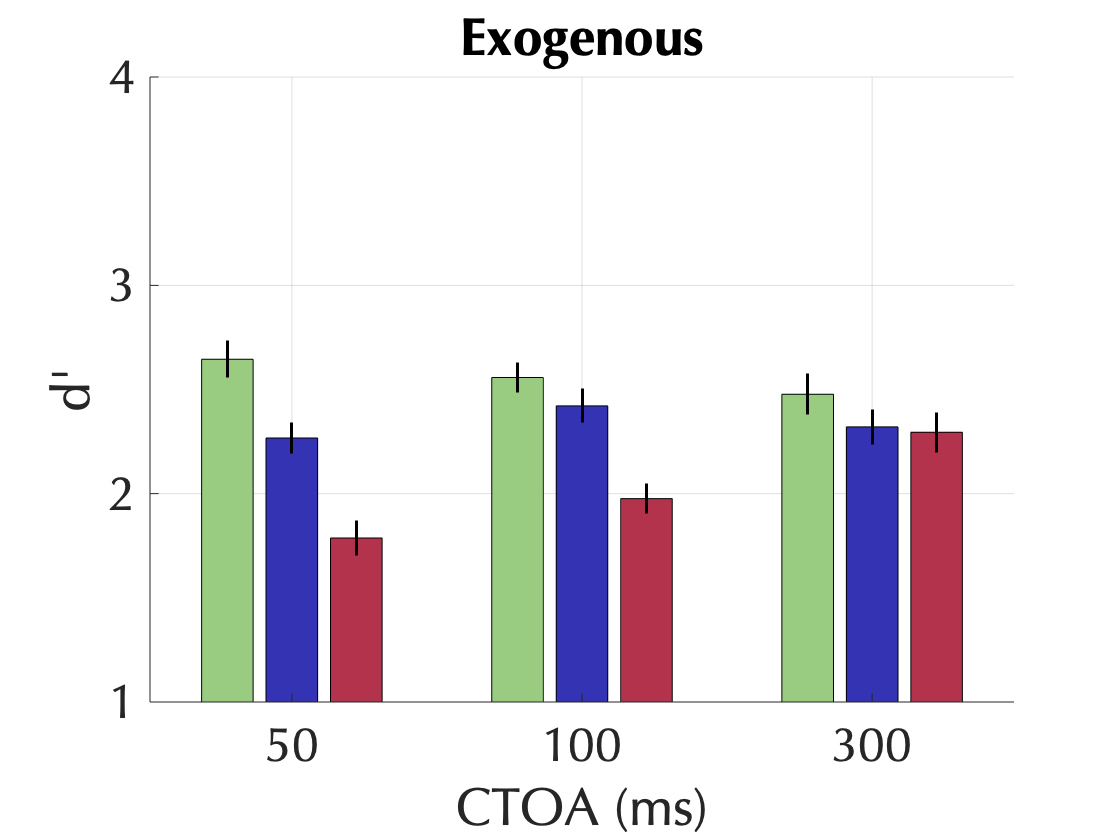

% Figure 2
valcol=[0.6 0.8 0.5]; neucol = [0.2 0.2 0.7]; InVcol = [0.7 0.2 0.3]; colBen =[0.1 0.6 0.6]; colEff =[0.9 0.8 0.2]; colCst =[0.8 0.2 0.8];
Valid_exo = [mean(exo_only.perf_Valid(exo_only.CTOAs =='50')), mean(exo_only.perf_Valid(exo_only.CTOAs =='100')), mean(exo_only.perf_Valid(exo_only.CTOAs =='300'))];
Neu_exo = [mean(exo_only.perf_Neutl(exo_only.CTOAs =='50')), mean(exo_only.perf_Neutl(exo_only.CTOAs =='100')), mean(exo_only.perf_Neutl(exo_only.CTOAs =='300'))];
InVal_exo = [mean(exo_only.perf_InVal(exo_only.CTOAs =='50')), mean(exo_only.perf_InVal(exo_only.CTOAs =='100')), mean(exo_only.perf_InVal(exo_only.CTOAs =='300'))];
err_Val_exo = [std(exo_only.perf_Valid(exo_only.CTOAs =='50')), std(exo_only.perf_Valid(exo_only.CTOAs =='100')), std(exo_only.perf_Valid(exo_only.CTOAs =='300'))]./sqrt(samp);
err_Neu_exo = [std(exo_only.perf_Neutl(exo_only.CTOAs =='50')), std(exo_only.perf_Neutl(exo_only.CTOAs =='100')), std(exo_only.perf_Neutl(exo_only.CTOAs =='300'))]./sqrt(samp);
err_InVal_exo = [std(exo_only.perf_InVal(exo_only.CTOAs =='50')), std(exo_only.perf_InVal(exo_only.CTOAs =='100')), std(exo_only.perf_InVal(exo_only.CTOAs =='300'))]./sqrt(samp);

figure
h=bar([Valid_exo;Neu_exo;InVal_exo]'); hold on 
for k=1:size(h,2)
        ctr(k,:) = bsxfun(@plus,h(1).XData, h(k).XOffset');
        ydt(k,:) = h(k).YData;
end
eh=errorbar(ctr',ydt',[err_Val_exo;err_Neu_exo;err_InVal_exo]','-k','LineStyle','none','CapSize',0,'LineWidth',1.5);
h(1).FaceColor ='Flat' ; h(1).CData=valcol;
h(2).FaceColor ='Flat' ; h(2).CData=neucol;
h(3).FaceColor ='Flat' ; h(3).CData=InVcol;
set(gca, 'xticklabels',{'50', '100', '300'}, 'FontSize', 20)
ylabel 'd'''
xlabel 'CTOA (ms)'
% legend('Valid', 'Neutral', 'Invalid')
ylim ([1 4])
title 'Exogenous'
grid on
set(gca, 'Box', 'off');
set(gca,'FontSize',24,'FontName','Optima')


clear ctr; clear ydt; clear h;

% Figure 2b 
valcol=[0.6 0.8 0.5]; neucol = [0.2 0.2 0.7]; InVcol = [0.7 0.2 0.3]; colBen =[0.1 0.6 0.6]; colEff =[0.9 0.8 0.2]; colCst =[0.8 0.2 0.8];
Valid_endo = [mean(endo_only.perf_Valid(endo_only.CTOAs =='100')), mean(endo_only.perf_Valid(endo_only.CTOAs =='300')), mean(endo_only.perf_Valid(endo_only.CTOAs =='600'))];
Neu_endo = [mean(endo_only.perf_Neutl(endo_only.CTOAs =='100')), mean(endo_only.perf_Neutl(endo_only.CTOAs =='300')), mean(endo_only.perf_Neutl(endo_only.CTOAs =='600'))];
err_Val_endo = [std(endo_only.perf_Valid(endo_only.CTOAs =='100')), std(endo_only.perf_Valid(endo_only.CTOAs =='300')), std(endo_only.perf_Valid(endo_only.CTOAs =='600'))]./sqrt(samp);
err_Neu_endo = [std(endo_only.perf_Neutl(endo_only.CTOAs =='100')), std(endo_only.perf_Neutl(endo_only.CTOAs =='300')), std(endo_only.perf_Neutl(endo_only.CTOAs =='600'))]./sqrt(samp);

figure
h=bar([Valid_endo;Neu_endo;]'); hold on 
for k=1:size(h,2)
        ctr(k,:) = bsxfun(@plus,h(1).XData, h(k).XOffset');
        ydt(k,:) = h(k).YData;
end
eh=errorbar(ctr',ydt',[err_Val_endo;err_Neu_endo]','-k','LineStyle','none','CapSize',0,'LineWidth',1.5);
h(1).FaceColor ='Flat' ; h(1).CData=valcol;
h(2).FaceColor ='Flat' ; h(2).CData=neucol;
set(gca, 'xticklabels',{'100', '300', '600'}, 'FontSize', 20)
ylabel 'd'''
xlabel 'CTOA (ms)'
title 'Endogenous'
% legend('Valid', 'Neutral')
ylim ([1 4])
grid on
set(gca, 'Box', 'off');
set(gca,'FontSize',24,'FontName','Optima')

clear ctr; clear ydt

## Only Neutral trials

% Is performance across all Neutral conditions consistent? - yes it is!
data4lme.CTOA_nom(data4lme.cueType=='endo' & data4lme.CTOAs=='100')=4;
data4lme.CTOA_nom(data4lme.cueType=='endo' & data4lme.CTOAs=='300')=5;
data4lme.CTOA_nom(data4lme.cueType=='endo' & data4lme.CTOAs=='600')=6;

lme = fitlme(data4lme, 'perf_Neutl ~ cueType + CTOAs + (cueType + CTOAs |subID)',"DummyVarCoding","effects")

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             168
    Fixed effects coefficients           5
    Random effects coefficients        140
    Covariance parameters               16

Formula:
    perf_Neutl ~ 1 + cueType + CTOAs + (1 + cueType + CTOAs | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    44.488    110.09    -1.2438          2.4875  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF     pValue        Lower        Upper    
    {'(Intercept)'}           2.3971    0.073346     32.683    163    1.8127e-73       2.2523        2.542
    {'cueType_exo'}        -0.054523     0.02064    -2.6416    163      0.009055     -0.09528    -0.013766
    {'CTOAs_50'   }         -0.07537    0.032704    -2.3046    163      0.022451     -0.13995    -0.010791
    {'CTOAs

anova(lme)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        1068.2    1      163    1.8127e-73
    {'cueType'    }         6.978    1      163      0.009055
    {'CTOAs'      }        2.2519    3      163      0.084319


lme1 = fitlme(exo_only,'perf_Neutl ~ CTOAs',"DummyVarCoding","effects")

lme1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations              84
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    perf_Neutl ~ 1 + CTOAs

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    99.552    109.27    -45.776          91.552  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF    pValue        Lower        Upper   
    {'(Intercept)'}           2.3365    0.045529     51.319    81    1.5184e-63       2.2459      2.4271
    {'CTOAs_50'   }        -0.069247    0.064388    -1.0755    81       0.28536     -0.19736    0.058865
    {'CTOAs_100'  }         0.085084    0.064388     1.3214    81       0.19008    -0.043029      0.2132

Random effects covariance parameters (95% CIs):

anova(lme1)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat      DF1    DF2    pValue    
    {'(Intercept)'}         2633.6    1      81     1.5184e-63
    {'CTOAs'      }        0.98775    2      81        0.37685


lme2 = fitlme(endo_only,'perf_Neutl ~  CTOAs',"DummyVarCoding","effects")

lme2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations              84
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    perf_Neutl ~ 1 + CTOAs

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    104.86    114.58    -48.429          96.858  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat       DF    pValue        Lower        Upper   
    {'(Intercept)'}           2.4768     0.04699      52.709    81    1.8547e-64       2.3833      2.5703
    {'CTOAs_100'  }        -0.055074    0.066454    -0.82875    81       0.40968      -0.1873    0.077149
    {'CTOAs_300'  }          0.06183    0.066454     0.93041    81       0.35492    -0.070394     0.19405

Random effects covariance parameters (95% CIs):

anova(lme2)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat      DF1    DF2    pValue    
    {'(Intercept)'}         2778.2    1      81     1.8547e-64
    {'CTOAs'      }        0.52094    2      81        0.59594



% How does sensitivity to letter recognition change with trial type: Valid, Neutral and inValid and
% CTOAs?
exo_acc = stack(exo_only,{'perf_Valid','perf_Neutl','perf_InVal'},'NewDataVariableName','dprimeAcc');
% exo_acc.dprimeAcc_centd = (exo_acc.dprimeAcc - mean(exo_acc.dprimeAcc));
exo_acc.dprimeAcc_Indicator = categorical(exo_acc.dprimeAcc_Indicator);
exo_acc.dprimeAcc_Indicator =reordercats(exo_acc.dprimeAcc_Indicator,{'perf_Neutl','perf_Valid','perf_InVal'});

lme3= fitlme(exo_acc, 'dprimeAcc ~ dprimeAcc_Indicator +CTOAs + (dprimeAcc_Indicator +CTOAs |subID)')

lme3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             252
    Fixed effects coefficients           5
    Random effects coefficients        140
    Covariance parameters               16

Formula:
    dprimeAcc ~ 1 + CTOAs + dprimeAcc_Indicator + (1 + CTOAs + dprimeAcc_Indicator | subID)

Model fit statistics:
    AIC       BIC      LogLikelihood    Deviance
    147.78    221.9    -52.891          105.78  

Fixed effects coefficients (95% CIs):
    Name                                      Estimate    SE          tStat      DF     pValue        Lower        Upper   
    {'(Intercept)'                   }          2.2645    0.078575     28.819    247    5.6692e-81       2.1097      2.4192
    {'CTOAs_100'                     }        0.085163    0.038456     2.2146    247      0.027702    0.0094203     0.16091
    {'CTOAs_300'                     }       

[PVAL3,F3,DF31,DF32]=lme3.coefTest

PVAL3 = 1.8909e-21

F3 = 31.9353

DF31 = 4

DF32 = 247

anova(lme3)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                           FStat     DF1    DF2    pValue    
    {'(Intercept)'        }        830.54    1      247    5.6692e-81
    {'CTOAs'              }        5.9234    2      247      0.003071
    {'dprimeAcc_Indicator'}         62.11    2      247    1.4079e-22



endo_acc = stack(endo_only,{'perf_Valid','perf_Neutl'},'NewDataVariableName','dprimeAcc');
endo_acc.dprimeAcc_Indicator = categorical(endo_acc.dprimeAcc_Indicator);

lme4= fitlme(endo_acc, 'dprimeAcc ~ dprimeAcc_Indicator + CTOAs +(dprimeAcc_Indicator + CTOAs |subID)')

lme4 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             168
    Fixed effects coefficients           4
    Random effects coefficients        112
    Covariance parameters               11

Formula:
    dprimeAcc ~ 1 + CTOAs + dprimeAcc_Indicator + (1 + CTOAs + dprimeAcc_Indicator | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    101.23    148.09    -35.615          71.23   

Fixed effects coefficients (95% CIs):
    Name                                      Estimate    SE          tStat      DF     pValue        Lower       Upper   
    {'(Intercept)'                   }         2.6838     0.088045     30.482    164    1.8835e-69      2.5099      2.8576
    {'CTOAs_300'                     }        0.19301     0.044103     4.3764    164    2.1409e-05     0.10593     0.28009
    {'CTOAs_600'                     }        

[PVAL4,F4,DF41,DF42]=lme4.coefTest

PVAL4 = 1.2584e-15

F4 = 30.2690

DF41 = 3

DF42 = 164

anova(lme4)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                           FStat     DF1    DF2    pValue    
    {'(Intercept)'        }        929.12    1      164    1.8835e-69
    {'CTOAs'              }        15.249    2      164    8.4382e-07
    {'dprimeAcc_Indicator'}        69.185    1      164    3.2914e-14



%Figure 3
%Time trace of cue benefits 
cueEff_exo=[mean(exo_only.cueEffAvg(exo_only.CTOAs == '50')); mean(exo_only.cueEffAvg(exo_only.CTOAs == '100'));mean(exo_only.cueEffAvg(exo_only.CTOAs == '300'))];
cueBen_exo=[mean(exo_only.cueBenAvg(exo_only.CTOAs == '50')); mean(exo_only.cueBenAvg(exo_only.CTOAs == '100'));mean(exo_only.cueBenAvg(exo_only.CTOAs == '300'))];
cueCst_exo=[mean(exo_only.cueCstAvg(exo_only.CTOAs == '50')); mean(exo_only.cueCstAvg(exo_only.CTOAs == '100'));mean(exo_only.cueCstAvg(exo_only.CTOAs == '300'))];

cueBen_endo=[mean(endo_only.cueBenAvg(endo_only.CTOAs == '100')); mean(endo_only.cueBenAvg(endo_only.CTOAs == '300'));mean(endo_only.cueBenAvg(endo_only.CTOAs == '600'))];
err_cB_endo=[std(endo_only.cueBenAvg(endo_only.CTOAs == '100')); std(endo_only.cueBenAvg(endo_only.CTOAs == '300'));std(endo_only.cueBenAvg(endo_only.CTOAs == '600'))]./sqrt(samp);
cueBen_endo

cueBen_endo =     0.1782
    0.3304
    0.5292


err_cB_endo

err_cB_endo =     0.0606
    0.0732
    0.0589


err_cB_exo=[std(exo_only.cueBenAvg(exo_only.CTOAs == '50')); std(exo_only.cueBenAvg(exo_only.CTOAs == '100'));std(exo_only.cueBenAvg(exo_only.CTOAs == '300'))]./sqrt(samp);
err_cC_exo=[std(exo_only.cueCstAvg(exo_only.CTOAs == '50')); std(exo_only.cueCstAvg(exo_only.CTOAs == '100'));std(exo_only.cueCstAvg(exo_only.CTOAs == '300'))]./sqrt(samp);
err_cE_exo=[std(exo_only.cueEffAvg(exo_only.CTOAs == '50')); std(exo_only.cueEffAvg(exo_only.CTOAs == '100'));std(exo_only.cueEffAvg(exo_only.CTOAs == '300'))]./sqrt(samp);
cueBen_exo

cueBen_exo =     0.3782
    0.1360
    0.1564


err_cB_exo

err_cB_exo =     0.0456
    0.0455
    0.0820


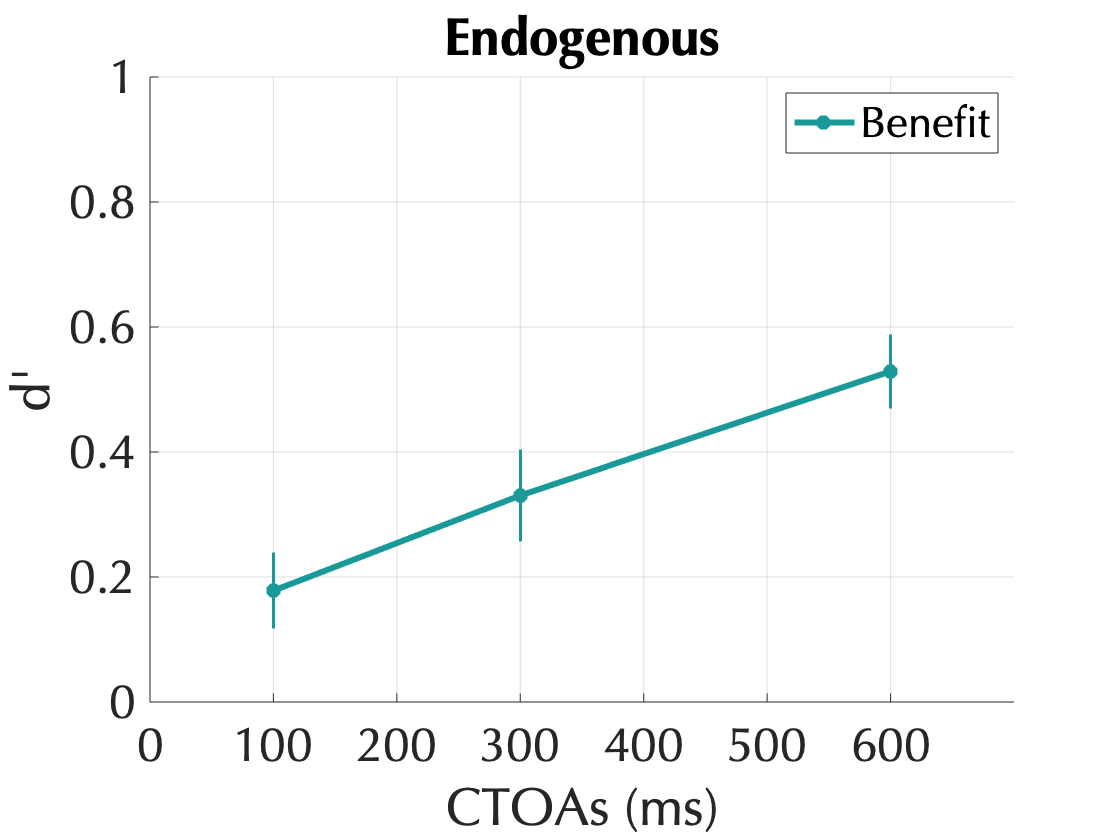

figure;
% plot([50 100 300],cueBen_exo,'o:','Color', colBen,'LineWidth',2,'MarkerSize',5)
hold on 
plot([100 300 600],cueBen_endo,'*-','Color', colBen,'LineWidth',3,'MarkerSize',5)

hold on 
% errorbar([50 100 300],cueBen_exo, err_cB_exo,'LineStyle','none','CapSize',0,'LineWidth',1.5,'Color',colBen,'CapSize',8);
hold on 
errorbar([100 300 600],cueBen_endo, err_cB_endo,'LineStyle','none','CapSize',0,'LineWidth',1.5,'Color',colBen);
hold on
xlim([0 700])
ylim ([0 1])
legend('Benefit')
xticks(0:100:600)
xlabel 'CTOAs (ms)'
ylabel 'd'''
title 'Endogenous'
set(gca,'FontSize',24,'FontName','Optima')
set(gca, 'Box', 'off');
grid on 

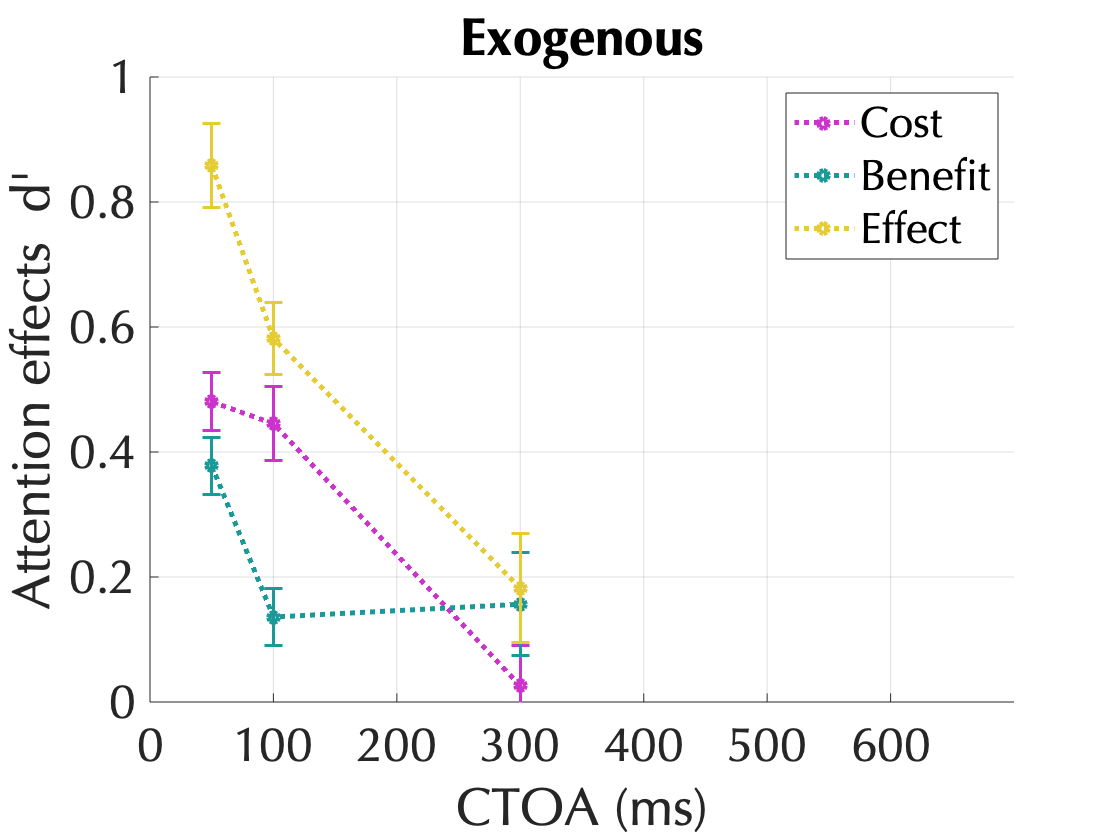


figure;
plot([50 100 300],cueCst_exo,'o:','Color', colCst,'LineWidth',2.5,'MarkerSize',5)
hold on 
plot([50 100 300],cueBen_exo,'o:','Color', colBen,'LineWidth',2.5,'MarkerSize',5)
hold on 
plot([50 100 300],cueEff_exo,'o:','Color', colEff,'LineWidth',2.5,'MarkerSize',5)
hold on 
errorbar([50 100 300],cueCst_exo, err_cC_exo,'LineStyle','none','CapSize',0,'LineWidth',1.5,'Color',colCst,'CapSize',8);
hold on 
errorbar([50 100 300],cueBen_exo, err_cB_exo,'LineStyle','none','CapSize',0,'LineWidth',1.5,'Color',colBen,'CapSize',8);
hold on 
errorbar([50 100 300],cueEff_exo, err_cE_exo,'LineStyle','none','CapSize',0,'LineWidth',1.5,'Color',colEff,'CapSize',8);
xlim([0 700])
ylim ([0 1])
xticks(0:100:600)
legend('Cost', 'Benefit','Effect')
xlabel 'CTOA (ms)'
ylabel 'Attention effects  d'''
title ('Exogenous')
set(gca,'FontSize',24,'FontName','Optima')
set(gca, 'Box', 'off');
grid on 

## Analysis- figure 3

% Fit a model to cue benefits, cost, effect with exo cue - with CTOAs as fixed effects
% and subjects random effects 
exo_only.CTOAs=reordercats(exo_only.CTOAs,{'50','100','300'});
lme5 = fitlme(exo_only, 'cueBenAvg ~ CTOAs + (CTOAs|subID)')

lme5 = Linear mixed-effects model fit by ML

Model information:
    Number of observations              84
    Fixed effects coefficients           3
    Random effects coefficients         84
    Covariance parameters                7

Formula:
    cueBenAvg ~ 1 + CTOAs + (1 + CTOAs | subID)

Model fit statistics:
    AIC       BIC      LogLikelihood    Deviance
    40.911    65.22    -10.456          20.911  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF    pValue        Lower       Upper    
    {'(Intercept)'}         0.37822    0.044769     8.4483    81     9.797e-13     0.28915       0.4673
    {'CTOAs_100'  }        -0.24227    0.060606    -3.9975    81    0.00014044    -0.36286     -0.12169
    {'CTOAs_300'  }         -0.2218    0.075049    -2.9554    81     0.0040887    -0.37112    -0.072473

Random effects covariance parameters

anova(lme5)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue   
    {'(Intercept)'}        71.374    1      81     9.797e-13
    {'CTOAs'      }          14.1    2      81     5.568e-06


% For other exogenous attentional effects
exo_only.CTOAs=reordercats(exo_only.CTOAs,{'50','100','300'});
lme5a = fitlme(exo_only, 'cueCstAvg ~ CTOAs + (CTOAs|subID)')

lme5a = Linear mixed-effects model fit by ML

Model information:
    Number of observations              84
    Fixed effects coefficients           3
    Random effects coefficients         84
    Covariance parameters                7

Formula:
    cueCstAvg ~ 1 + CTOAs + (1 + CTOAs | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    49.279    73.587    -14.639          29.279  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat       DF    pValue        Lower       Upper   
    {'(Intercept)'}          0.48022    0.045497      10.555    81    6.9754e-17      0.3897     0.57075
    {'CTOAs_100'  }        -0.034769    0.066851    -0.52009    81       0.60442    -0.16778    0.098245
    {'CTOAs_300'  }         -0.45438    0.081809     -5.5541    81     3.447e-07    -0.61715     -0.2916

Random effects covariance par

anova(lme5a)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        111.41    1      81     6.9754e-17
    {'CTOAs'      }        17.612    2      81     4.4573e-07


lme5b = fitlme(exo_only, 'cueEffAvg ~ CTOAs + (CTOAs|subID)')

lme5b = Linear mixed-effects model fit by ML

Model information:
    Number of observations              84
    Fixed effects coefficients           3
    Random effects coefficients         84
    Covariance parameters                7

Formula:
    cueEffAvg ~ 1 + CTOAs + (1 + CTOAs | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    82.148    106.46    -31.074          62.148  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF    pValue        Lower       Upper   
    {'(Intercept)'}         0.85845    0.065544     13.097    81     1.065e-21     0.72804     0.98886
    {'CTOAs_100'  }        -0.27704    0.069671    -3.9764    81    0.00015125    -0.41566    -0.13842
    {'CTOAs_300'  }        -0.67617    0.098606    -6.8573    81    1.2699e-09    -0.87237    -0.47998

Random effects covariance parameters 

anova(lme5b)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        171.54    1      81      1.065e-21
    {'CTOAs'      }        24.081    2      81     6.2046e-09



%---Endo
endo_only.CTOAs=reordercats(endo_only.CTOAs,{'600','300','100'});
lme6 = fitlme(endo_only, 'cueBenAvg ~ CTOAs + (CTOAs|subID)')

lme6 = Linear mixed-effects model fit by ML

Model information:
    Number of observations              84
    Fixed effects coefficients           3
    Random effects coefficients         84
    Covariance parameters                7

Formula:
    cueBenAvg ~ 1 + CTOAs + (1 + CTOAs | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    71.171    95.479    -25.585          51.171  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF    pValue        Lower       Upper    
    {'(Intercept)'}         0.52916    0.057887     9.1412    81    4.1777e-14     0.41398      0.64434
    {'CTOAs_300'  }        -0.19878    0.085948    -2.3128    81      0.023274    -0.36979    -0.027767
    {'CTOAs_100'  }        -0.35099     0.08328    -4.2146    81    6.4607e-05    -0.51669     -0.18529

Random effects covariance paramete

anova(lme6,'dfmethod','residual')

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        83.561    1      81     4.1777e-14
    {'CTOAs'      }        8.8855    2      81     0.00032444


% Now look at the interaction just for the CTOAs that exist in both cue types - 
% for supplementary  
endoexo = data4lme(data4lme.CTOAs == '100' | data4lme.CTOAs == '300',:);
endoexo.CTOAs = removecats(endoexo.CTOAs);
lme7 = fitlme(endoexo, 'cueBenAvg ~ CTOAs  +(CTOAs*cueType|subID)','DummyVarCoding',"effects")

lme7 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             112
    Fixed effects coefficients           2
    Random effects coefficients        112
    Covariance parameters               11

Formula:
    cueBenAvg ~ 1 + CTOAs + (1 + cueType*CTOAs | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    91.273    126.61    -32.636          65.273  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF     pValue        Lower       Upper   
    {'(Intercept)'}          0.19196    0.031598     6.0749    110    1.8159e-08     0.12934     0.25458
    {'CTOAs_100'  }        -0.054215    0.036392    -1.4898    110       0.13915    -0.12634    0.017905

Random effects covariance parameters (95% CIs):
Group: subID (28 Levels)
    Name1                            Name2   

anova(lme7,'dfmethod','residual')

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        36.904    1      110    1.8159e-08
    {'CTOAs'      }        2.2194    1      110       0.13915


%[PVAL7,F7,DF71,DF72]=lme7.coefTest
%ttest to compare the non-overlapping CTOAs - vartest2 shows that the 2
%samples are of the same variance 
[H,P, CI, STATS]=ttest(exo_only.cueBenAvg(exo_only.CTOAs == '50'), endo_only.cueBenAvg(endo_only.CTOAs == '600'))

H = 1

P = 0.0437

CI =    -0.2973
   -0.0046


STATS = struct with fields:
    tstat: -2.1157
       df: 27
       sd: 0.3775


r = 0.0864

p = 0.6621

% Figure 4 - W-profiles, cue - benefit function 
%Prepare data
% data4pos.cueType = categorical(data4pos.cueType,[0, 1],{'exo','endo'});
data4pos.CTOAs = categorical(data4pos.CTOAs);
data4pos.position = categorical(data4pos.position);
wprofile_data = data4pos(data4pos.CTOAs == '50' | data4pos.CTOAs == '600',:);
wprofile_data_endo= data4pos(data4pos.cueType == 'endo' & data4pos.CTOAs == '600',:);
wprofile_data_exo= data4pos(data4pos.cueType == 'exo' & data4pos.CTOAs == '50',:);
wprofile_data.cueEffect(wprofile_data.cueType=='endo')= wprofile_data.cueBenefit(wprofile_data.cueType=='endo');

yV_exo= [mean(wprofile_data_exo.dpVal(wprofile_data_exo.position =='1')),mean(wprofile_data_exo.dpVal(wprofile_data_exo.position =='2')),mean(wprofile_data_exo.dpVal(wprofile_data_exo.position =='3')),mean(wprofile_data_exo.dpVal(wprofile_data_exo.position =='4')),mean(wprofile_data_exo.dpVal(wprofile_data_exo.position =='5')),mean(wprofile_data_exo.dpVal(wprofile_data_exo.position =='6'))];
erryV_exo= [std(wprofile_data_exo.dpVal(wprofile_data_exo.position =='1')),std(wprofile_data_exo.dpVal(wprofile_data_exo.position =='2')),std(wprofile_data_exo.dpVal(wprofile_data_exo.position =='3')),std(wprofile_data_exo.dpVal(wprofile_data_exo.position =='4')),std(wprofile_data_exo.dpVal(wprofile_data_exo.position =='5')),std(wprofile_data_exo.dpVal(wprofile_data_exo.position =='6'))]./sqrt(samp);

yN_exo= [mean(wprofile_data_exo.dpNeu(wprofile_data_exo.position =='1')),mean(wprofile_data_exo.dpNeu(wprofile_data_exo.position =='2')),mean(wprofile_data_exo.dpNeu(wprofile_data_exo.position =='3')),mean(wprofile_data_exo.dpNeu(wprofile_data_exo.position =='4')),mean(wprofile_data_exo.dpNeu(wprofile_data_exo.position =='5')),mean(wprofile_data_exo.dpNeu(wprofile_data_exo.position =='6'))];
erryN_exo= [std(wprofile_data_exo.dpNeu(wprofile_data_exo.position =='1')),std(wprofile_data_exo.dpNeu(wprofile_data_exo.position =='2')),std(wprofile_data_exo.dpNeu(wprofile_data_exo.position =='3')),std(wprofile_data_exo.dpNeu(wprofile_data_exo.position =='4')),std(wprofile_data_exo.dpNeu(wprofile_data_exo.position =='5')),std(wprofile_data_exo.dpNeu(wprofile_data_exo.position =='6'))]./sqrt(samp);

yI_exo= [mean(wprofile_data_exo.dpInV(wprofile_data_exo.position =='1')),mean(wprofile_data_exo.dpInV(wprofile_data_exo.position =='2')),mean(wprofile_data_exo.dpInV(wprofile_data_exo.position =='3')),mean(wprofile_data_exo.dpInV(wprofile_data_exo.position =='4')),mean(wprofile_data_exo.dpInV(wprofile_data_exo.position =='5')),mean(wprofile_data_exo.dpInV(wprofile_data_exo.position =='6'))];
erryI_exo= [std(wprofile_data_exo.dpInV(wprofile_data_exo.position =='1')),std(wprofile_data_exo.dpInV(wprofile_data_exo.position =='2')),std(wprofile_data_exo.dpInV(wprofile_data_exo.position =='3')),std(wprofile_data_exo.dpInV(wprofile_data_exo.position =='4')),std(wprofile_data_exo.dpInV(wprofile_data_exo.position =='5')),std(wprofile_data_exo.dpInV(wprofile_data_exo.position =='6'))]./sqrt(samp);

yV_endo = [mean(wprofile_data_endo.dpVal(wprofile_data_endo.position=='1')),mean(wprofile_data_endo.dpVal(wprofile_data_endo.position=='2')),mean(wprofile_data_endo.dpVal(wprofile_data_endo.position=='3')),mean(wprofile_data_endo.dpVal(wprofile_data_endo.position=='4')),mean(wprofile_data_endo.dpVal(wprofile_data_endo.position=='5')),mean(wprofile_data_endo.dpVal(wprofile_data_endo.position=='6'))];
erryV_endo = [std(wprofile_data_endo.dpVal(wprofile_data_endo.position=='1')),std(wprofile_data_endo.dpVal(wprofile_data_endo.position=='2')),std(wprofile_data_endo.dpVal(wprofile_data_endo.position=='3')),std(wprofile_data_endo.dpVal(wprofile_data_endo.position=='4')),std(wprofile_data_endo.dpVal(wprofile_data_endo.position=='5')),std(wprofile_data_endo.dpVal(wprofile_data_endo.position=='6'))]./sqrt(samp);

yN_endo = [mean(wprofile_data_endo.dpNeu(wprofile_data_endo.position=='1')),mean(wprofile_data_endo.dpNeu(wprofile_data_endo.position=='2')),mean(wprofile_data_endo.dpNeu(wprofile_data_endo.position=='3')),mean(wprofile_data_endo.dpNeu(wprofile_data_endo.position=='4')),mean(wprofile_data_endo.dpNeu(wprofile_data_endo.position=='5')),mean(wprofile_data_endo.dpNeu(wprofile_data_endo.position=='6'))];
erryN_endo = [std(wprofile_data_endo.dpNeu(wprofile_data_endo.position=='1')),std(wprofile_data_endo.dpNeu(wprofile_data_endo.position=='2')),std(wprofile_data_endo.dpNeu(wprofile_data_endo.position=='3')),std(wprofile_data_endo.dpNeu(wprofile_data_endo.position=='4')),std(wprofile_data_endo.dpNeu(wprofile_data_endo.position=='5')),std(wprofile_data_endo.dpNeu(wprofile_data_endo.position=='6'))]./sqrt(samp);

cueBen_exo_wprof = [mean(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='1')),mean(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='2')),mean(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='3')),mean(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='4')),mean(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='5')),mean(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='6'))];
cueBen_exo_wperr = [std(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='1')),std(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='2')),std(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='3')),std(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='4')),std(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='5')),std(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='6'))]./sqrt(size(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='6'),1));

cueCst_exo_wprof = [mean(wprofile_data_exo.cueCst(wprofile_data_exo.position =='1')),mean(wprofile_data_exo.cueCst(wprofile_data_exo.position =='2')),mean(wprofile_data_exo.cueCst(wprofile_data_exo.position =='3')),mean(wprofile_data_exo.cueCst(wprofile_data_exo.position =='4')),mean(wprofile_data_exo.cueCst(wprofile_data_exo.position =='5')),mean(wprofile_data_exo.cueCst(wprofile_data_exo.position =='6'))];
cueCst_exo_wperr = [std(wprofile_data_exo.cueCst(wprofile_data_exo.position =='1')),std(wprofile_data_exo.cueCst(wprofile_data_exo.position =='2')),std(wprofile_data_exo.cueCst(wprofile_data_exo.position =='3')),std(wprofile_data_exo.cueCst(wprofile_data_exo.position =='4')),std(wprofile_data_exo.cueCst(wprofile_data_exo.position =='5')),std(wprofile_data_exo.cueCst(wprofile_data_exo.position =='6'))]./sqrt(samp);

cueEff_exo_wprof = [mean(wprofile_data_exo.cueEffect(wprofile_data_exo.position =='1')),mean(wprofile_data_exo.cueEffect(wprofile_data_exo.position =='2')),mean(wprofile_data_exo.cueEffect(wprofile_data_exo.position =='3')),mean(wprofile_data_exo.cueEffect(wprofile_data_exo.position =='4')),mean(wprofile_data_exo.cueEffect(wprofile_data_exo.position =='5')),mean(wprofile_data_exo.cueEffect(wprofile_data_exo.position =='6'))];
cueEff_exo_wperr = [std(wprofile_data_exo.cueEffect(wprofile_data_exo.position =='1')),std(wprofile_data_exo.cueEffect(wprofile_data_exo.position =='2')),std(wprofile_data_exo.cueEffect(wprofile_data_exo.position =='3')),std(wprofile_data_exo.cueEffect(wprofile_data_exo.position =='4')),std(wprofile_data_exo.cueEffect(wprofile_data_exo.position =='5')),std(wprofile_data_exo.cueEffect(wprofile_data_exo.position =='6'))]./sqrt(samp);

cueBen_endo_wprof = [mean(wprofile_data_endo.cueBenefit(wprofile_data_endo.position =='1')),mean(wprofile_data_endo.cueBenefit(wprofile_data_endo.position =='2')),mean(wprofile_data_endo.cueBenefit(wprofile_data_endo.position =='3')),mean(wprofile_data_endo.cueBenefit(wprofile_data_endo.position =='4')),mean(wprofile_data_endo.cueBenefit(wprofile_data_endo.position =='5')),mean(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='6'))];
cueBen_endo_wperr = [std(wprofile_data_endo.cueBenefit(wprofile_data_endo.position =='1')),std(wprofile_data_endo.cueBenefit(wprofile_data_endo.position =='2')),std(wprofile_data_endo.cueBenefit(wprofile_data_endo.position =='3')),std(wprofile_data_endo.cueBenefit(wprofile_data_endo.position =='4')),std(wprofile_data_endo.cueBenefit(wprofile_data_endo.position =='5')),std(wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='6'))]./sqrt(size((wprofile_data_exo.cueBenefit(wprofile_data_exo.position =='6')),1));

## Data Prep - Cuebenefits at the crowded versus the uncrowded positions

% creating a dummy variable to code if the position is a crowded position
% or an uncrowded position
%  wprofile_data.crowdedPositions=[];
wprofile_data.crowdedPositions(wprofile_data.position=="2" | wprofile_data.position=="5",:)=1;
wprofile_data.crowdedPositions(wprofile_data.position=="1" | wprofile_data.position=="6",:)=0;
wprofile_data.crowdedPositions=categorical(wprofile_data.crowdedPositions);

%Letter position  
%  wprofile_data.outerPositions=[];
wprofile_data.outerPositions(wprofile_data.position=="1" | wprofile_data.position=="6",:)=0;
wprofile_data.outerPositions(wprofile_data.position=="2" | wprofile_data.position=="5",:)=1;
wprofile_data.outerPositions(wprofile_data.position=="3" | wprofile_data.position=="4",:)=-1;
wprofile_data.outerPositions=categorical(wprofile_data.outerPositions);

%Code for hemifield effects
%  wprofile_data.Hem=[];
wprofile_data.Hem(wprofile_data.position=="1" | wprofile_data.position=="2"| wprofile_data.position=="3",:)=0;
wprofile_data.Hem(wprofile_data.position=="4" | wprofile_data.position=="5"| wprofile_data.position=="6",:)=1;

%   wprofile_data_endo.crowdedPositions=[];
wprofile_data_endo.crowdedPositions(wprofile_data_endo.position=="2" | wprofile_data_endo.position=="5" ,:)=1;
wprofile_data_endo.crowdedPositions(wprofile_data_endo.position=="1" | wprofile_data_endo.position=="6",:)=0;
wprofile_data_endo.crowdedPositions=categorical(wprofile_data_endo.crowdedPositions);

%Code for hemifield effects 
%   wprofile_data_endo.Hem=[];
wprofile_data_endo.Hem(wprofile_data_endo.position=="1" | wprofile_data_endo.position=="2"| wprofile_data_endo.position=="3",:)=0;
wprofile_data_endo.Hem(wprofile_data_endo.position=="4" | wprofile_data_endo.position=="5"| wprofile_data_endo.position=="6",:)=1;


%   wprofile_data_endo.outerPositions=[];
wprofile_data_endo.outerPositions(wprofile_data_endo.position=="1" | wprofile_data_endo.position=="6",:)=0;
wprofile_data_endo.outerPositions(wprofile_data_endo.position=="2" | wprofile_data_endo.position=="5",:)=1;
wprofile_data_endo.outerPositions(wprofile_data_endo.position=="3" | wprofile_data_endo.position=="4",:)=-1;
wprofile_data_endo.outerPositions=categorical(wprofile_data_endo.outerPositions);

%     wprofile_data_exo.crowdedPositions=[];
wprofile_data_exo.crowdedPositions(wprofile_data_exo.position=="2" | wprofile_data_exo.position=="5",:)=1;
wprofile_data_exo.crowdedPositions(wprofile_data_exo.position=="1" | wprofile_data_exo.position=="6",:)=0;
wprofile_data_exo.crowdedPositions=categorical(wprofile_data_exo.crowdedPositions);

%Code for hemifield effects 
wprofile_data_exo.Hem(wprofile_data_exo.position=="1" | wprofile_data_exo.position=="2"| wprofile_data_exo.position=="3",:)=0;
wprofile_data_exo.Hem(wprofile_data_exo.position=="4" | wprofile_data_exo.position=="5"| wprofile_data_exo.position=="6",:)=1;

%  wprofile_data_exo.outerPositions=[];
wprofile_data_exo.outerPositions(wprofile_data_exo.position=="1" | wprofile_data_exo.position=="6",:)=0;%least crowded
wprofile_data_exo.outerPositions(wprofile_data_exo.position=="2" | wprofile_data_exo.position=="5",:)=1;% most crowded
 wprofile_data_exo.outerPositions(wprofile_data_exo.position=="3" | wprofile_data_exo.position=="4",:)=-1;
wprofile_data_exo.outerPositions=categorical(wprofile_data_exo.outerPositions);

% GEt the average across differnt positions
cB_outerpositions_exo = [mean(wprofile_data_exo.cueBenefit(wprofile_data_exo.outerPositions=='0')), mean(wprofile_data_exo.cueBenefit(wprofile_data_exo.outerPositions=='1'))];
err_cB_outerpositions_exo = [std(wprofile_data_exo.cueBenefit(wprofile_data_exo.outerPositions=='0')), std(wprofile_data_exo.cueBenefit(wprofile_data_exo.outerPositions=='1'))]./sqrt(size(wprofile_data_exo.cueBenefit(wprofile_data_exo.outerPositions=='1'),1));
cB_outerpositions_endo = [mean(wprofile_data_endo.cueBenefit(wprofile_data_endo.outerPositions=='0')), mean(wprofile_data_endo.cueBenefit(wprofile_data_endo.outerPositions=='1'))];
err_cB_outerpositions_endo = [std(wprofile_data_endo.cueBenefit(wprofile_data_endo.outerPositions=='0')), std(wprofile_data_endo.cueBenefit(wprofile_data_endo.outerPositions=='1'))]./sqrt(size(wprofile_data_endo.cueBenefit(wprofile_data_endo.outerPositions=='1'),1));

%GEt the mean for the peak and trough of the w-profiles 
cB_crowded_exo = [mean(wprofile_data_exo.cueBenefit(wprofile_data_exo.crowdedPositions=='0')),mean(wprofile_data_exo.cueBenefit(wprofile_data_exo.crowdedPositions=='1'))];
err_cB_crowded_exo = [std(wprofile_data_exo.cueBenefit(wprofile_data_exo.crowdedPositions=='0')),std(wprofile_data_exo.cueBenefit(wprofile_data_exo.crowdedPositions=='1'))]./sqrt(size(wprofile_data_exo.cueBenefit(wprofile_data_exo.crowdedPositions=='1'),1));
cB_crowded_endo = [mean(wprofile_data_endo.cueBenefit(wprofile_data_endo.crowdedPositions=='0')),mean(wprofile_data_endo.cueBenefit(wprofile_data_endo.crowdedPositions=='1'))];
err_cB_crowded_endo = [std(wprofile_data_endo.cueBenefit(wprofile_data_endo.crowdedPositions=='0')),std(wprofile_data_endo.cueBenefit(wprofile_data_endo.crowdedPositions=='1'))]./sqrt(size(wprofile_data_endo.cueBenefit(wprofile_data_endo.crowdedPositions=='1'),1));

rHem_exo=mean(wprofile_data_exo.cueBenefit(wprofile_data_exo.Hem==1));
lHem_exo=mean(wprofile_data_exo.cueBenefit(wprofile_data_exo.Hem==0));
errRHem_exo = std(wprofile_data_exo.cueBenefit(wprofile_data_exo.Hem==1))./sqrt(size(wprofile_data.cueBenefit(wprofile_data_exo.Hem==1),1));
errLHem_exo = std(wprofile_data_exo.cueBenefit(wprofile_data_exo.Hem==0))./sqrt(size(wprofile_data.cueBenefit(wprofile_data_exo.Hem==0),1));

rHem_endo=mean(wprofile_data_endo.cueBenefit(wprofile_data_endo.Hem==1));
lHem_endo=mean(wprofile_data_endo.cueBenefit(wprofile_data_endo.Hem==0));
errRHem_endo = std(wprofile_data_endo.cueBenefit(wprofile_data_endo.Hem==1))./sqrt(size(wprofile_data.cueBenefit(wprofile_data_endo.Hem==1),1));
errLHem_endo = std(wprofile_data_endo.cueBenefit(wprofile_data_endo.Hem==0))./sqrt(size(wprofile_data.cueBenefit(wprofile_data_endo.Hem==0),1));

## Figure 4 a and b W-profiles 

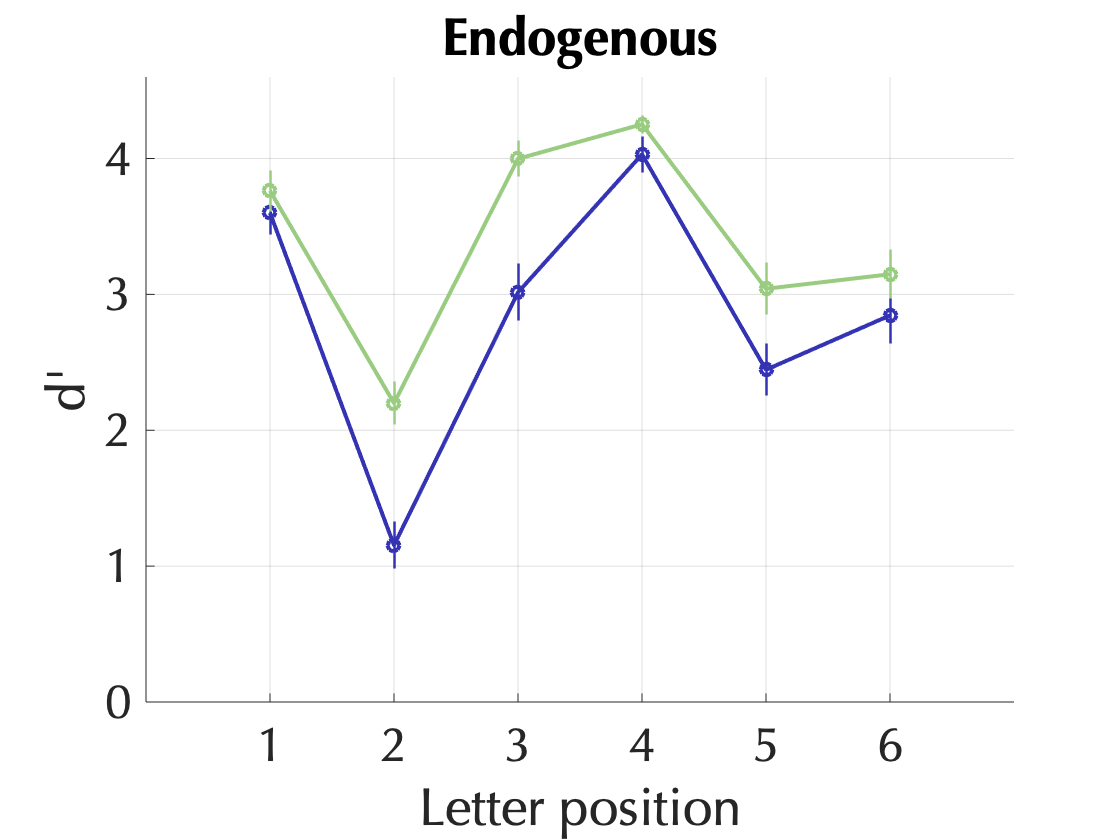

%Figure 4 a and b
figure;
plot(yV_endo, 'o-','Color',valcol,'LineWidth',2)
hold on 
plot(yN_endo, 'o-','Color',neucol,'LineWidth',2)
hold on 
errorbar(yN_endo,erryN_endo,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',neucol);
hold on
errorbar(yV_endo,erryV_endo,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',valcol);
hold on 
xlim([0 7])
xticks(1:1:6)
ylim([0 4.6])
xlabel 'Letter position'
ylabel 'd'''
title 'Endogenous'
% % legend({'Valid','Neutral'})
set(gca,'FontSize',24,'FontName','Optima') 
set(gca, 'box','off')
grid on 

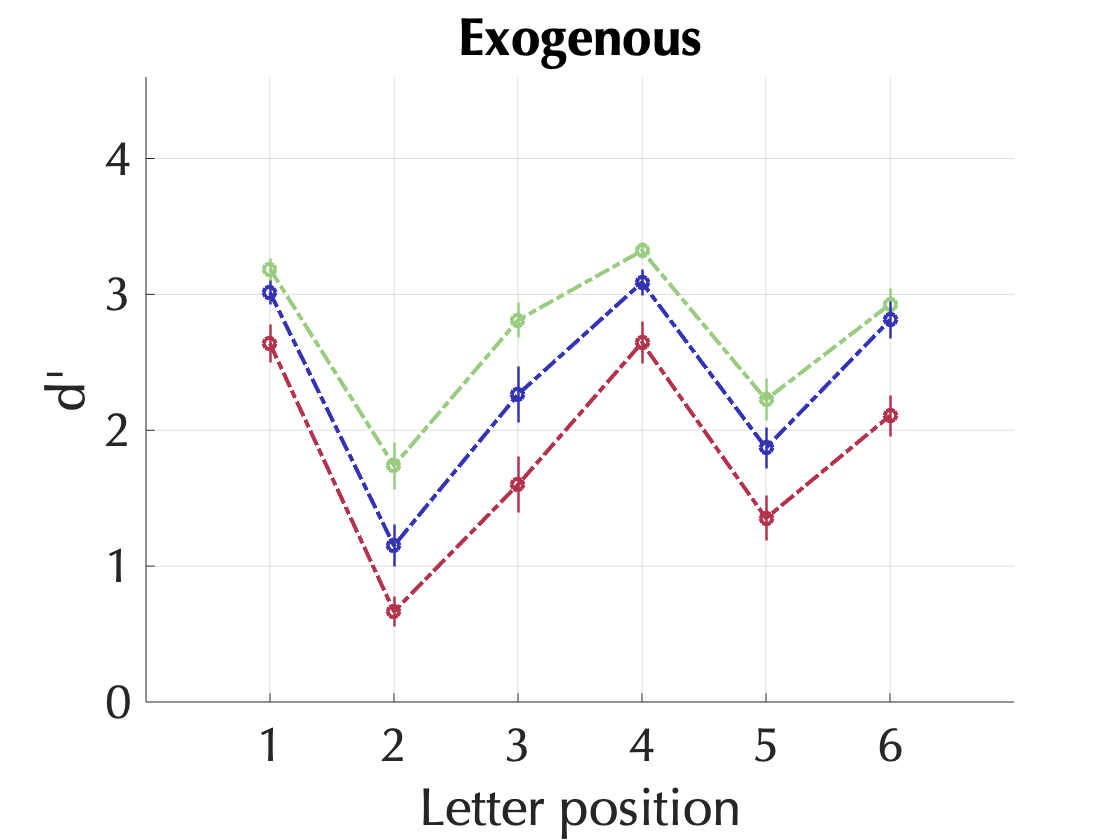


figure;
plot(yV_exo, 'o-.','Color',valcol,'LineWidth',2)
hold on 
plot(yN_exo, 'o-.','Color',neucol,'LineWidth',2)
hold on
plot(yI_exo, 'o-.','Color',InVcol,'LineWidth',2)
hold on
errorbar(yV_exo,erryV_exo,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',valcol);
hold on 
errorbar(yI_exo,erryI_exo,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',InVcol);
hold on 
errorbar(yN_exo,erryN_exo,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',neucol);

xlim([0 7])
xticks(1:1:6)
ylim([0 4.6])
xlabel 'Letter position'
ylabel 'd'''
title 'Exogenous'
% legend({'Valid', 'Neutral','InValid'})
set(gca,'FontSize',24,'FontName','Optima')
set(gca, 'box','off')
grid on 

## Figure 4c and d

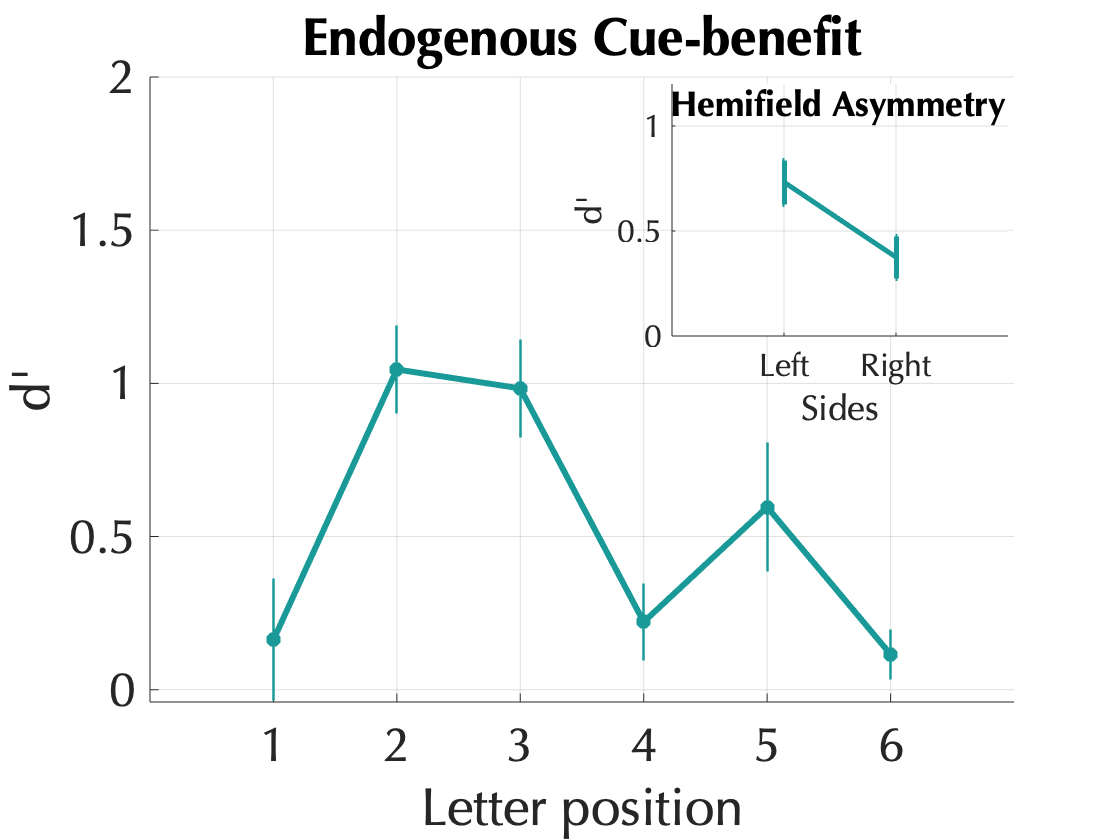

figure;
hold on 
plot(cueBen_endo_wprof,'*-','Color',colBen,'LineWidth',3)
hold on 
errorbar(cueBen_endo_wprof,cueBen_endo_wperr,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',colBen);
hold on 
xlim([0 7])
xticks(1:1:6)
ylim([-0.04 2])
xlabel 'Letter position'
ylabel 'd'''
title('Endogenous Cue-benefit')
set(gca,'FontSize',24,'FontName','Optima')
set(gca,'box','off')
grid on
axes('Position',[.6 .6 .3 .3])
box on
hold on 
% errorbar([lHem_exo,rHem_exo] ,[errRHem_exo,errLHem_exo],'LineStyle',':','CapSize',5,'LineWidth',2.2,'Color',colBen)
hold on 
 errorbar([lHem_endo,rHem_endo], [errLHem_endo,errRHem_endo],'LineStyle','-','CapSize',0.2,'LineWidth',2.5,'Color',colBen)
hold on 
ylim([0 1.2])
xlim([0, 3])
xticks([1:2])
xticklabels({'Left','Right'})
xlabel 'Sides'
ylabel 'd'''
set(gca,'FontName','Optima','FontSize',16)
set(gca,'box','off')
grid on
title ('Hemifield Asymmetry','Position', [1.48, 1, 0])

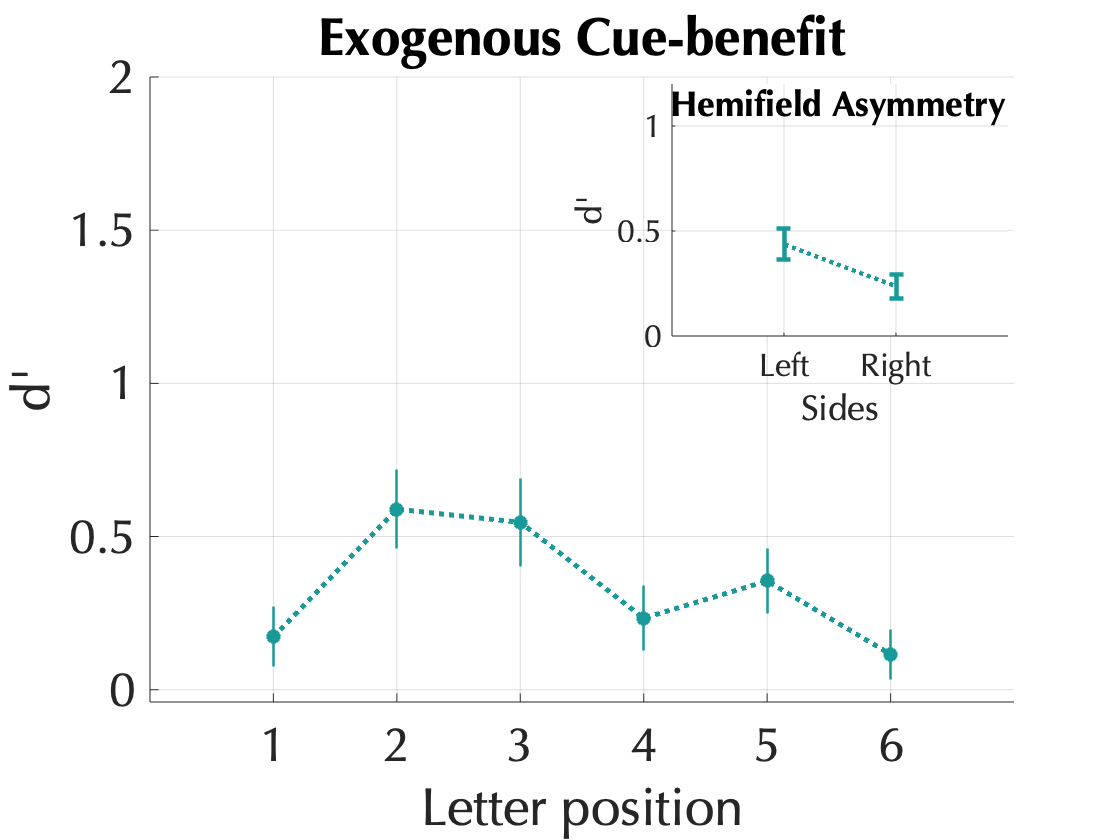


figure;
hold on
plot(cueBen_exo_wprof,'*:','Color',colBen,'LineWidth',2.5)
hold on
errorbar(cueBen_exo_wprof,cueBen_exo_wperr, 'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',colBen);
hold on

xlim([0 7])
xticks(1:1:6)
ylim([-0.04 2])

xlabel 'Letter position'
ylabel 'd'''
title ('Exogenous Cue-benefit')
set(gca,'FontSize',24,'FontName','Optima')
set(gca,'box','off')
grid on
axes('Position',[.6 .6 .3 .3])
box on
hold on 
errorbar([lHem_exo,rHem_exo] ,[errLHem_exo,errRHem_exo],'LineStyle',':','CapSize',5,'LineWidth',2.2,'Color',colBen)
hold on 
ylim([0 1.2])
xlim([0, 3])
xticks([1:2])
xticklabels({'Left','Right'})
xlabel 'Sides'
ylabel 'd'''
set(gca,'FontName','Optima','FontSize',16)
set(gca,'box','off')
grid on
title ('Hemifield Asymmetry','Position', [1.48, 1, 0])

##  Figure 5 a and b

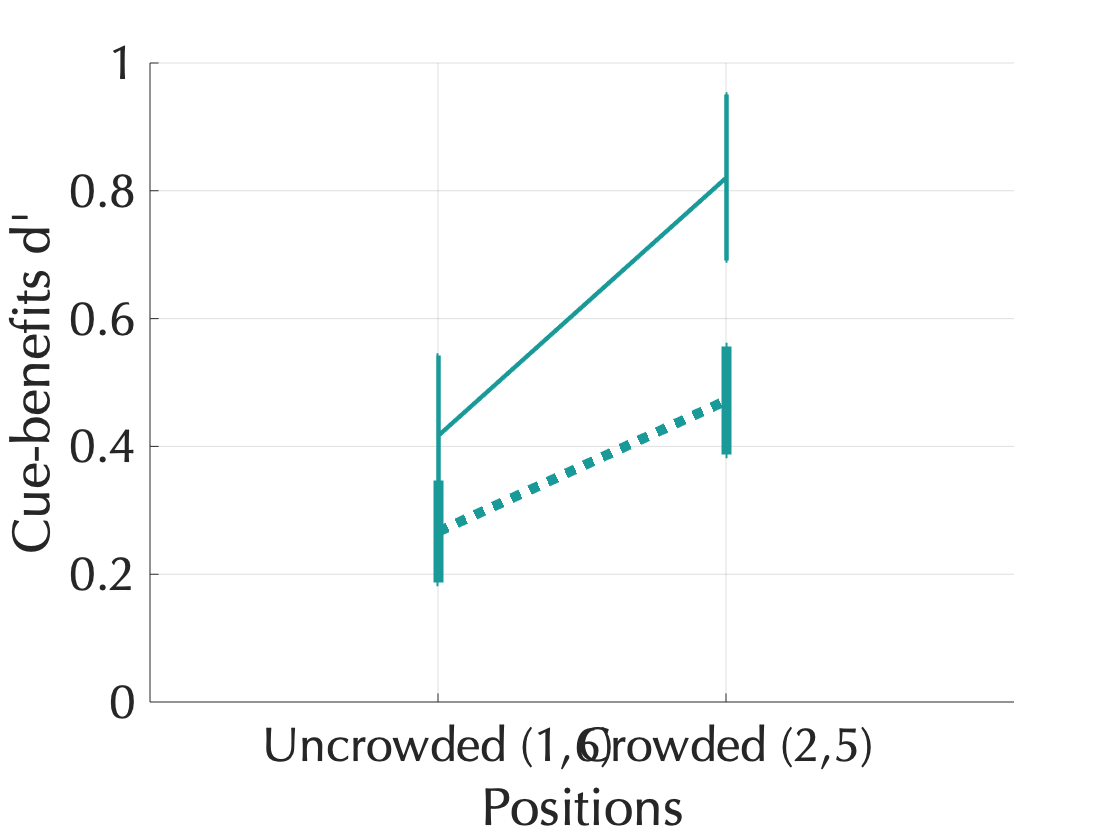

figure;
% h= bar([cB_crowded_exo; cB_crowded_endo]);
% h(1).FaceColor ='Flat' ; h(1).CData=colBen;
hold on 
errorbar(cB_crowded_exo ,err_cB_crowded_exo,'LineStyle',':','CapSize',.2,'LineWidth',5,'Color',colBen)
hold on 
errorbar(cB_crowded_endo, err_cB_crowded_endo,'LineStyle','-','CapSize',0.2,'LineWidth',2.2,'Color',colBen)
hold on 
ylim([0 1])
xlim([0, 3])
xticks([1:2])
xticklabels({'Uncrowded (1,6)','Crowded (2,5)'})
xlabel 'Positions'
ylabel 'Cue-benefits d'''
set(gca,'FontSize',24,'FontName','Optima')
set(gca,'box','off')
grid on

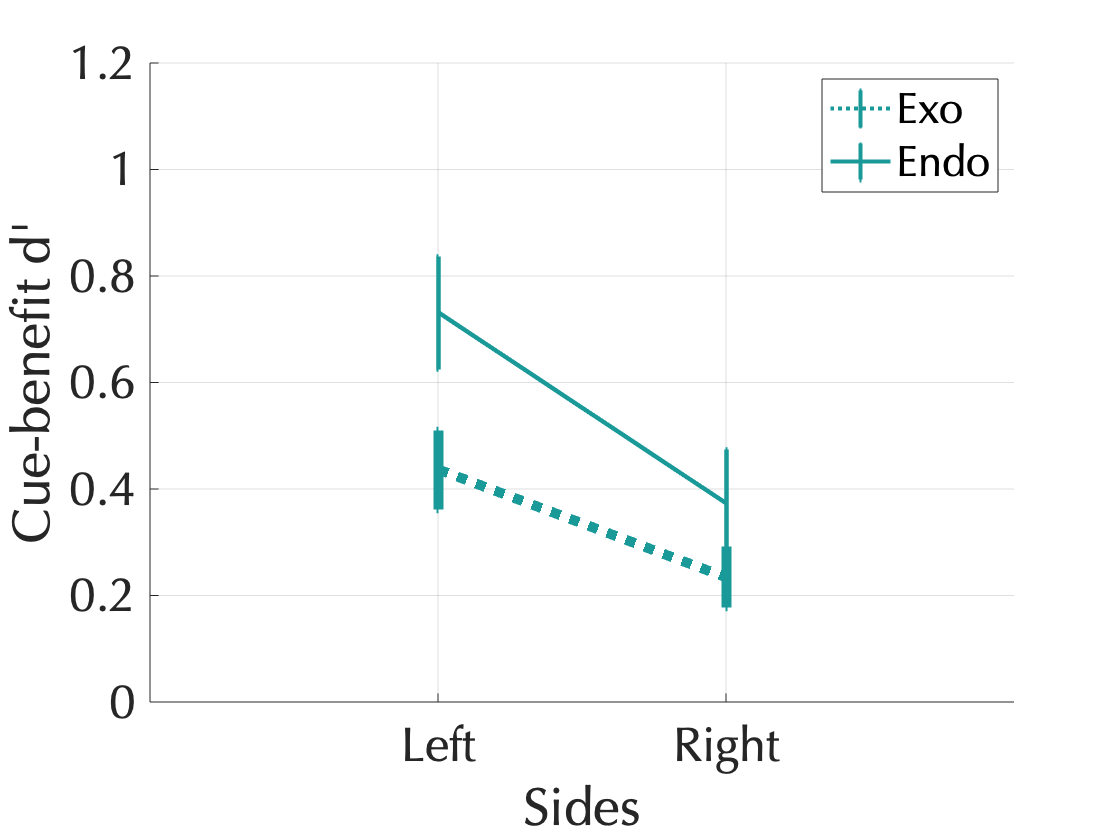

% legend({'Exo','Endo'})

figure;
% h= bar([cB_crowded_exo; cB_crowded_endo]);
% h(1).FaceColor ='Flat' ; h(1).CData=colBen;
hold on 
errorbar([lHem_exo,rHem_exo] ,[errLHem_exo,errRHem_exo],'LineStyle',':','CapSize',.2,'LineWidth',5,'Color',colBen)
hold on 
errorbar([lHem_endo,rHem_endo], [errLHem_endo,errRHem_endo],'LineStyle','-','CapSize',0.2,'LineWidth',2.2,'Color',colBen)
hold on 
ylim([0 1.2])
xlim([0, 3])
xticks([1:2])
xticklabels({'Left','Right'})
xlabel 'Sides'
ylabel 'Cue-benefit d'''
set(gca,'FontSize',24,'FontName','Optima')
set(gca,'box','off')
grid on
legend({'Exo','Endo'})

## Analysis serial position function for cue benefits

% Fit a model to cue benefit with cue type and positions as predictors 
lme8 = fitlme(wprofile_data, 'cueBenefit ~ cueType * position + (cueType * position | subID)','DummyVarCoding',"effects")
anova(lme8) 

% for each cue type 
%Exo
lme9 = fitlme(wprofile_data_exo, 'cueBenefit ~ position +(position| subID)','DummyVarCoding',"effects")
anova(lme9)
%Endo
lme10 = fitlme(wprofile_data_endo,'cueBenefit ~ position +(position| subID)','DummyVarCoding',"effects")
anova(lme10)


## Analysis - cue benefits acros

wprofile_data_relPositions = wprofile_data(wprofile_data.position=='1' |wprofile_data.position=='2'|wprofile_data.position=='5'|wprofile_data.position=='6',:);
lme11= fitlme(wprofile_data_relPositions, 'cueBenefit ~ cueType * crowdedPositions + (cueType *crowdedPositions | subID)','DummyVarCoding',"effects")

lme11 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             224
    Fixed effects coefficients           4
    Random effects coefficients        112
    Covariance parameters               11

Formula:
    cueBenefit ~ 1 + cueType*crowdedPositions + (1 + cueType*crowdedPositions | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    536.25    587.42    -253.12          506.25  

Fixed effects coefficients (95% CIs):
    Name                                      Estimate    SE          tStat      DF     pValue        Lower        Upper   
    {'(Intercept)'                   }         0.41742    0.062927     6.6335    220    2.5095e-10      0.29341     0.54144
    {'cueType_exo'                   }        -0.10932    0.065038    -1.6808    220      0.094219      -0.2375    0.018861
    {'crowdedPositions_0'            }         

anova(lme11)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                                FStat     DF1    DF2    pValue    
    {'(Intercept)'             }        44.003    1      220    2.5095e-10
    {'cueType'                 }        2.8251    1      220      0.094219
    {'crowdedPositions'        }        15.883    1      220    9.1657e-05
    {'cueType:crowdedPositions'}        1.4491    1      220       0.22997


lme_grps= fitlme(wprofile_data, 'cueBenefit ~ cueType * crowdedPositions + (cueType *crowdedPositions | subID)')

lme_grps = Linear mixed-effects model fit by ML

Model information:
    Number of observations             336
    Fixed effects coefficients           4
    Random effects coefficients        112
    Covariance parameters               11

Formula:
    cueBenefit ~ 1 + cueType*crowdedPositions + (1 + cueType*crowdedPositions | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    814.69    871.95    -392.35          784.69  

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE          tStat     DF     pValue       Lower        Upper  
    {'(Intercept)'                    }        0.26697     0.072366    3.6892    332    0.0002628      0.12462    0.40932
    {'cueType_endo'                   }         0.1506      0.10717    1.4052    332      0.16089    -0.060223    0.36142
    {'crowdedPositions_1'             }        0.2

anova(lme_grps)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                                FStat     DF1    DF2    pValue   
    {'(Intercept)'             }         13.61    1      332    0.0002628
    {'cueType'                 }        1.9746    1      332      0.16089
    {'crowdedPositions'        }        2.6934    1      332      0.10171
    {'cueType:crowdedPositions'}        1.1831    1      332      0.27751


lme11a= fitlme(wprofile_data, 'cueBenefit ~ cueType * outerPositions + (cueType * outerPositions | subID)','DummyVarCoding',"effects")
anova(lme11a)
lme11b= fitlme(wprofile_data, 'cueBenefit ~ cueType * position + (cueType * position | subID)','DummyVarCoding',"effects")
anova(lme11b)
lme11c= fitlme(wprofile_data, 'cueBenefit ~ cueType * Hem + (cueType * Hem | subID)','DummyVarCoding',"effects")
anova(lme11c)
%Exo
wprofile_exo_relPositions = wprofile_data_exo(wprofile_data_exo.position=='1' |wprofile_data_exo.position=='2'|wprofile_data_exo.position=='5'|wprofile_data_exo.position=='6',:);
lme12 = fitlme(wprofile_exo_relPositions, 'cueBenefit ~  crowdedPositions + (crowdedPositions| subID)','DummyVarCoding',"effects")
anova(lme12)
lme12a = fitlme(wprofile_data_exo, 'cueBenefit ~  outerPositions + (outerPositions| subID)','DummyVarCoding',"effects")
anova(lme12a)
lme12b = fitlme(wprofile_data_exo, 'cueBenefit ~  Hem + ( Hem | subID)','DummyVarCoding',"effects")
anova(lme12b)
%Endo
wprofile_endo_relPositions = wprofile_data_endo(wprofile_data_endo.position=='1' |wprofile_data_endo.position=='2'|wprofile_data_endo.position=='5'|wprofile_data_endo.position=='6',:);
lme13 = fitlme(wprofile_endo_relPositions, 'cueBenefit ~ crowdedPositions + (crowdedPositions| subID)','DummyVarCoding',"effects")
anova(lme13)
lme13a = fitlme(wprofile_data_endo, 'cueBenefit ~ outerPositions + (outerPositions| subID)','DummyVarCoding',"effects")
anova(lme13a)
lme13b = fitlme(wprofile_data_endo, 'cueBenefit ~  Hem + (Hem | subID)','DummyVarCoding',"effects")
anova(lme13b)
%Hemifield effects 
lme_hemi = fitlme(wprofile_data, 'cueBenefit ~ cueType * Hem + (cueType *Hem | subID)','DummyVarCoding',"effects")
anova(lme_hemi)

## Error analysis - Data Prep

err_Exo = Data4pos(Data4pos.cueType =='exo',:); 
err_Endo = Data4pos(Data4pos.cueType =='endo',:);
err_ExoOn = Data4pos(Data4pos.cueType =='exoOn',:);

err_Exo_50 = err_Exo(err_Exo.CTOAs =='50',:);
err_Exo_100 = err_Exo(err_Exo.CTOAs =='100',:);
err_Exo_300 = err_Exo(err_Exo.CTOAs =='300',:);

err_Endo_100 = err_Endo(err_Endo.CTOAs =='100',:);
err_Endo_300 = err_Endo(err_Endo.CTOAs =='300',:);
err_Endo_600 = err_Endo(err_Endo.CTOAs =='600',:);

% Linearize data
% To linearize the data we norm invervse the proportions and for this to work -
% we need to get rid of zeros.
% Add atleast 1 incorrect trial to norm inverse
err_Exo_50.pSwaps_I(find(err_Exo_50.pSwaps_I==0))=0.1;
err_Exo_50.pSwaps_V(find(err_Exo_50.pSwaps_V==0))=0.1;
err_Exo_50.pSwaps_N(find(err_Exo_50.pSwaps_N==0))=0.1;
err_Exo_50.misID_I(find(err_Exo_50.misID_I==0))=0.1;
err_Exo_50.misID_N(find(err_Exo_50.misID_N==0))=0.1;
err_Exo_50.misID_V(find(err_Exo_50.misID_V==0))=0.1;

% Add at least one error to use norminverse
err_Endo_600.pSwaps_V(find(err_Endo_600.pSwaps_V==0))=0.1;
err_Endo_600.pSwaps_N(find(err_Endo_600.pSwaps_N==0))=0.1;
err_Endo_600.misID_V(find(err_Endo_600.misID_V==0))=0.1;
err_Endo_600.misID_N(find(err_Endo_600.misID_N==0))=0.1;

%Linearize proportion data using norminv
err_Exo_50.pSwaps_I= norminv((((err_Exo_50.pSwaps_I))));
err_Exo_50.pSwaps_V= norminv((((err_Exo_50.pSwaps_V))));
err_Exo_50.pSwaps_N= norminv((((err_Exo_50.pSwaps_N))));
err_Exo_50.misID_I= norminv((((err_Exo_50.misID_I))));
err_Exo_50.misID_V= norminv((((err_Exo_50.misID_V))));
err_Exo_50.misID_N=norminv((((err_Exo_50.misID_N))));

err_Endo_600.pSwaps_N =norminv((((err_Endo_600.pSwaps_N)))); 
err_Endo_600.pSwaps_V =norminv((((err_Endo_600.pSwaps_V)))); 
err_Endo_600.misID_N = norminv((((err_Endo_600.misID_N )))); 
err_Endo_600.misID_V =norminv((((err_Endo_600.misID_V )))); 

## Errors - Plot Figure 6 a and b 

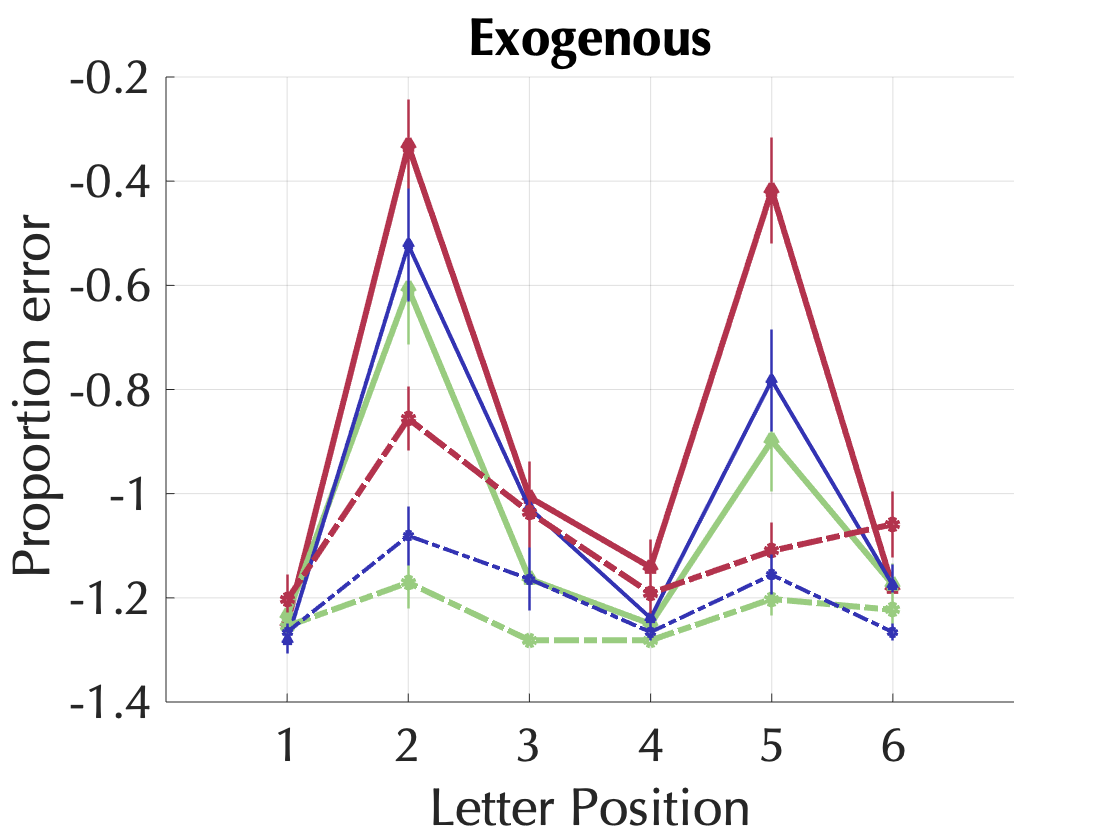

figure; hold on
yI =[nanmean(err_Exo_50.pSwaps_I(err_Exo_50.position =="1")),mean(err_Exo_50.pSwaps_I(err_Exo_50.position =="2")),...
mean(err_Exo_50.pSwaps_I(err_Exo_50.position =="3")),mean(err_Exo_50.pSwaps_I(err_Exo_50.position =="4")),mean(err_Exo_50.pSwaps_I(err_Exo_50.position =="5")),...
mean(err_Exo_50.pSwaps_I(err_Exo_50.position =="6"))];

errY=[std(err_Exo_50.pSwaps_I(err_Exo_50.position =="1")),std(err_Exo_50.pSwaps_I(err_Exo_50.position =="2")),...
std(err_Exo_50.pSwaps_I(err_Exo_50.position =="3")),std(err_Exo_50.pSwaps_I(err_Exo_50.position =="4")),std(err_Exo_50.pSwaps_I(err_Exo_50.position =="5")),...
std(err_Exo_50.pSwaps_I(err_Exo_50.position =="6"))]./sqrt(samp);

plot(yI,'^-','Color',InVcol,'MarkerSize',5,'LineWidth',3)
hold on 
errorbar(yI, errY,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',InVcol);
hold on

yV =[mean(err_Exo_50.pSwaps_V(err_Exo_50.position =="1")),mean(err_Exo_50.pSwaps_V(err_Exo_50.position =="2")),...
mean(err_Exo_50.pSwaps_V(err_Exo_50.position =="3")),mean(err_Exo_50.pSwaps_V(err_Exo_50.position =="4")),mean(err_Exo_50.pSwaps_V(err_Exo_50.position =="5")),...
mean(err_Exo_50.pSwaps_V(err_Exo_50.position =="6"))];

errY=[std(err_Exo_50.pSwaps_V(err_Exo_50.position =="1")),std(err_Exo_50.pSwaps_V(err_Exo_50.position =="2")),...
std(err_Exo_50.pSwaps_V(err_Exo_50.position =="3")),std(err_Exo_50.pSwaps_V(err_Exo_50.position =="4")),std(err_Exo_50.pSwaps_V(err_Exo_50.position =="5")),...
std(err_Exo_50.pSwaps_V(err_Exo_50.position =="6"))]./sqrt(samp);

plot(yV,'^-','Color',valcol,'MarkerSize',5,'LineWidth',3)
hold on 
errorbar(yV, errY,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',valcol);
hold on 
yN=[mean(err_Exo_50.pSwaps_N(err_Exo_50.position =="1")),mean(err_Exo_50.pSwaps_N(err_Exo_50.position =="2")),...
mean(err_Exo_50.pSwaps_N(err_Exo_50.position =="3")),mean(err_Exo_50.pSwaps_N(err_Exo_50.position =="4")),mean(err_Exo_50.pSwaps_N(err_Exo_50.position =="5")),...
mean(err_Exo_50.pSwaps_N(err_Exo_50.position =="6"))];

errYN=[std(err_Exo_50.pSwaps_N(err_Exo_50.position =="1")),std(err_Exo_50.pSwaps_N(err_Exo_50.position =="2")),...
std(err_Exo_50.pSwaps_N(err_Exo_50.position =="3")),std(err_Exo_50.pSwaps_N(err_Exo_50.position =="4")),std(err_Exo_50.pSwaps_N(err_Exo_50.position =="5")),...
std(err_Exo_50.pSwaps_N(err_Exo_50.position =="6"))]./sqrt(samp);

plot(yN,'^-','Color',neucol,'MarkerSize',4,'LineWidth',2)
hold on 
errorbar(yN, errY,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',neucol);
hold on 

yI_mis = [mean(err_Exo_50.misID_I(err_Exo_50.position =="1")),mean(err_Exo_50.misID_I(err_Exo_50.position =="2")),...
mean(err_Exo_50.misID_I(err_Exo_50.position =="3")),mean(err_Exo_50.misID_I(err_Exo_50.position =="4")),mean(err_Exo_50.misID_I(err_Exo_50.position =="5")),...
mean(err_Exo_50.misID_I(err_Exo_50.position =="6"))];

errYV_mis=[std(err_Exo_50.misID_I(err_Exo_50.position =="1")),std(err_Exo_50.misID_I(err_Exo_50.position =="2")),...
std(err_Exo_50.misID_I(err_Exo_50.position =="3")),std(err_Exo_50.misID_I(err_Exo_50.position =="4")),std(err_Exo_50.misID_I(err_Exo_50.position =="5")),...
std(err_Exo_50.misID_I(err_Exo_50.position =="6"))]./sqrt(samp);

plot(yI_mis,'o','Color',InVcol,'MarkerSize',5,'LineWidth',3,'LineStyle',"-.")
hold on 
errorbar(yI_mis, errYV_mis,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',InVcol);
hold on 

yV_mis = [mean(err_Exo_50.misID_V(err_Exo_50.position =="1")),mean(err_Exo_50.misID_V(err_Exo_50.position =="2")),...
mean(err_Exo_50.misID_V(err_Exo_50.position =="3")),mean(err_Exo_50.misID_V(err_Exo_50.position =="4")),mean(err_Exo_50.misID_V(err_Exo_50.position =="5")),...
mean(err_Exo_50.misID_V(err_Exo_50.position =="6"))];

errYV_mis=[std(err_Exo_50.misID_V(err_Exo_50.position =="1")),std(err_Exo_50.misID_V(err_Exo_50.position =="2")),...
std(err_Exo_50.misID_V(err_Exo_50.position =="3")),std(err_Exo_50.misID_V(err_Exo_50.position =="4")),std(err_Exo_50.misID_V(err_Exo_50.position =="5")),...
std(err_Exo_50.misID_V(err_Exo_50.position =="6"))]./sqrt(samp);

plot(yV_mis,'o','Color',valcol,'MarkerSize',5,'LineWidth',3,'LineStyle',"-.")
hold on 
errorbar(yV_mis, errYV_mis,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',valcol);
hold on 

yN_mis = [mean(err_Exo_50.misID_N(err_Exo_50.position =="1")),mean(err_Exo_50.misID_N(err_Exo_50.position =="2")),...
mean(err_Exo_50.misID_N(err_Exo_50.position =="3")),mean(err_Exo_50.misID_N(err_Exo_50.position =="4")),mean(err_Exo_50.misID_N(err_Exo_50.position =="5")),...
mean(err_Exo_50.misID_N(err_Exo_50.position =="6"))];

errYN_mis=[std(err_Exo_50.misID_N(err_Exo_50.position =="1")),std(err_Exo_50.misID_N(err_Exo_50.position =="2")),...
std(err_Exo_50.misID_N(err_Exo_50.position =="3")),std(err_Exo_50.misID_N(err_Exo_50.position =="4")),std(err_Exo_50.misID_N(err_Exo_50.position =="5")),...
std(err_Exo_50.misID_N(err_Exo_50.position =="6"))]./sqrt(samp);

plot(yN_mis,'o','Color',neucol,'MarkerSize',4,'LineWidth',2,'LineStyle',"-.")
hold on 
errorbar(yN_mis, errYN_mis,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',neucol);
hold on 
% line((1:6),repmat(p_InCx_Swap,[1, 6]))
xlim([0 7])
xticks(1:1:6)
ylabel 'Proportion error '
xlabel 'Letter Position'
title 'Exogenous'
set(gca,'FontSize',24,'FontName','Optima')
% ylim([0 0.7])
grid on 

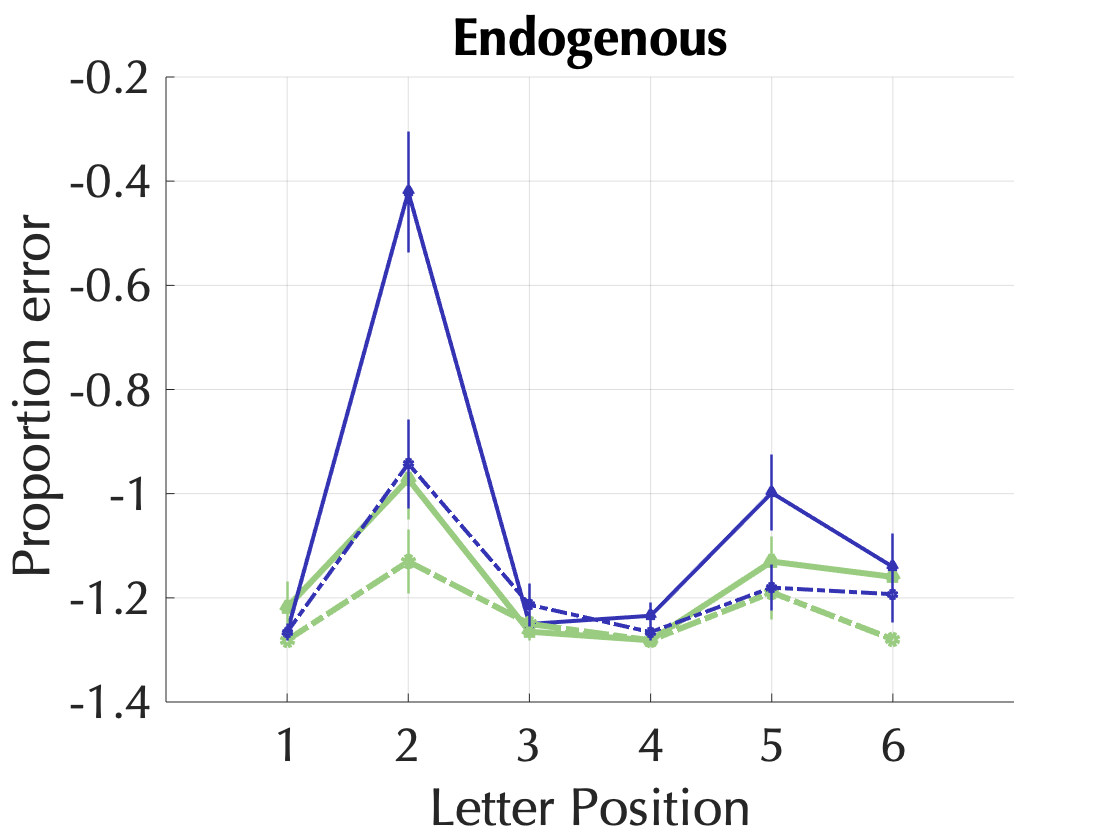


%% Endogenous 
y_V= [mean(err_Endo_600.pSwaps_V(err_Endo_600.position =="1")),mean(err_Endo_600.pSwaps_V(err_Endo_600.position =="2")),...
mean(err_Endo_600.pSwaps_V(err_Endo_600.position =="3")),mean(err_Endo_600.pSwaps_V(err_Endo_600.position =="4")),mean(err_Endo_600.pSwaps_V(err_Endo_600.position =="5")),...
mean(err_Endo_600.pSwaps_V(err_Endo_600.position =="6"))];

errY_V=[std(err_Endo_600.pSwaps_V(err_Endo_600.position =="1")),std(err_Endo_600.pSwaps_V(err_Endo_600.position =="2")),...
std(err_Endo_600.pSwaps_V(err_Endo_600.position =="3")),std(err_Endo_600.pSwaps_V(err_Endo_600.position =="4")),std(err_Endo_600.pSwaps_V(err_Endo_600.position =="5")),...
std(err_Endo_600.pSwaps_V(err_Endo_600.position =="6"))]./sqrt(samp);

y_N =[mean(err_Endo_600.pSwaps_N(err_Endo_600.position =="1")),mean(err_Endo_600.pSwaps_N(err_Endo_600.position =="2")),...
mean(err_Endo_600.pSwaps_N(err_Endo_600.position =="3")),mean(err_Endo_600.pSwaps_N(err_Endo_600.position =="4")),mean(err_Endo_600.pSwaps_N(err_Endo_600.position =="5")),...
mean(err_Endo_600.pSwaps_N(err_Endo_600.position =="6"))] ; 

errY_N =[std(err_Endo_600.pSwaps_N(err_Endo_600.position =="1")),std(err_Endo_600.pSwaps_N(err_Endo_600.position =="2")),...
std(err_Endo_600.pSwaps_N(err_Endo_600.position =="3")),std(err_Endo_600.pSwaps_N(err_Endo_600.position =="4")),std(err_Endo_600.pSwaps_N(err_Endo_600.position =="5")),...
std(err_Endo_600.pSwaps_N(err_Endo_600.position =="6"))]./sqrt(samp);
%Misidentification error
y_Vmis = [mean(err_Endo_600.misID_V(err_Endo_600.position =="1")),mean(err_Endo_600.misID_V(err_Endo_600.position =="2")),...
mean(err_Endo_600.misID_V(err_Endo_600.position =="3")),mean(err_Endo_600.misID_V(err_Endo_600.position =="4")),mean(err_Endo_600.misID_V(err_Endo_600.position =="5")),...
mean(err_Endo_600.misID_V(err_Endo_600.position =="6"))];

errY_Vmis = [std(err_Endo_600.misID_V(err_Endo_600.position =="1")),std(err_Endo_600.misID_V(err_Endo_600.position =="2")),...
std(err_Endo_600.misID_V(err_Endo_600.position =="3")),std(err_Endo_600.misID_V(err_Endo_600.position =="4")),std(err_Endo_600.misID_V(err_Endo_600.position =="5")),...
std(err_Endo_600.misID_V(err_Endo_600.position =="6"))]./sqrt(samp);

y_Nmis =[mean(err_Endo_600.misID_N(err_Endo_600.position =="1")),mean(err_Endo_600.misID_N(err_Endo_600.position =="2")),...
mean(err_Endo_600.misID_N(err_Endo_600.position =="3")),mean(err_Endo_600.misID_N(err_Endo_600.position =="4")),mean(err_Endo_600.misID_N(err_Endo_600.position =="5")),...
mean(err_Endo_600.misID_N(err_Endo_600.position =="6"))]; 

errY_Nmis = [std(err_Endo_600.misID_N(err_Endo_600.position =="1")),std(err_Endo_600.misID_N(err_Endo_600.position =="2")),...
std(err_Endo_600.misID_N(err_Endo_600.position =="3")),std(err_Endo_600.misID_N(err_Endo_600.position =="4")),std(err_Endo_600.misID_N(err_Endo_600.position =="5")),...
std(err_Endo_600.misID_N(err_Endo_600.position =="6"))]./sqrt(samp);
%Plot-------
figure; hold on 
plot(y_V,'^-','Color',valcol,'MarkerSize',5,'LineWidth',3)
hold on 
plot(y_N,'^-','Color',neucol,'MarkerSize',4,'LineWidth',2)
hold on
plot(y_Vmis,'o','Color',valcol,'MarkerSize',5,'LineWidth',3,'LineStyle',"-.")
hold on 
plot(y_Nmis,'o','Color',neucol,'MarkerSize',4,'LineWidth',2,'LineStyle',"-.")
hold on 

errorbar(y_V, errY_V,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',valcol);
hold on 
 
errorbar(y_N, errY_N,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',neucol);
hold on 

errorbar(y_Vmis, errY_Vmis,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',valcol);
hold on 

errorbar(y_Nmis, errY_Nmis,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',neucol);
hold on 

xlim([0 7])
xticks(1:1:6)
ylabel 'Proportion error '
xlabel 'Letter Position'
title 'Endogenous'
set(gca,'FontSize',24,'FontName','Optima')
% legend({'TranspositionError:Valid',':Neutral','Misidentification:Valid',':Neutral'})
%  ylim([0 0.5])
grid on 

## Figure 6 c and d 

err_Endo_600.difSwap=(err_Endo_600.pSwaps_N-err_Endo_600.pSwaps_V);
err_Endo_600.difmisD=(err_Endo_600.misID_N-err_Endo_600.misID_V);

y_diffSwaps = [mean(err_Endo_600.difSwap(err_Endo_600.position=='1')),mean(err_Endo_600.difSwap(err_Endo_600.position=='2')),...
    mean(err_Endo_600.difSwap(err_Endo_600.position=='3')),mean(err_Endo_600.difSwap(err_Endo_600.position=='4')),mean(err_Endo_600.difSwap(err_Endo_600.position=='5')),...
    mean(err_Endo_600.difSwap(err_Endo_600.position=='6'))];
errYDswaps = [std(err_Endo_600.difSwap(err_Endo_600.position=='1')),std(err_Endo_600.difSwap(err_Endo_600.position=='2')),...
    std(err_Endo_600.difSwap(err_Endo_600.position=='3')),std(err_Endo_600.difSwap(err_Endo_600.position=='4')),std(err_Endo_600.difSwap(err_Endo_600.position=='5')),...
    std(err_Endo_600.difSwap(err_Endo_600.position=='6'))]./sqrt(samp);
y_diffmis = [mean(err_Endo_600.difmisD(err_Endo_600.position=='1')),mean(err_Endo_600.difmisD(err_Endo_600.position=='2')),...
    mean(err_Endo_600.difmisD(err_Endo_600.position=='3')),mean(err_Endo_600.difmisD(err_Endo_600.position=='4')),mean(err_Endo_600.difmisD(err_Endo_600.position=='5')),...
    mean(err_Endo_600.difmisD(err_Endo_600.position=='6'))];
errYDmis = [std(err_Endo_600.difmisD(err_Endo_600.position=='1')),std(err_Endo_600.difmisD(err_Endo_600.position=='2')),...
    std(err_Endo_600.difmisD(err_Endo_600.position=='3')),std(err_Endo_600.difmisD(err_Endo_600.position=='4')),std(err_Endo_600.difmisD(err_Endo_600.position=='5')),...
    std(err_Endo_600.difmisD(err_Endo_600.position=='6'))]./sqrt(samp);

figure; 
plot(y_diffSwaps,'^','MarkerSize',5,'LineWidth',3,'LineStyle',"-",'Color',[.6 0.2 .6])
hold on 
plot(y_diffmis,'^','MarkerSize',5,'LineWidth',4,'LineStyle',":",'Color',[.4 0.1 .6])
hold on 
errorbar(y_diffSwaps, errYDswaps,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',[.6 0.2 .6]);
hold on 
errorbar(y_diffmis, errYDmis,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',[.4 0.1 .4]);
hold on 
xlim([0 7])
xticks(1:1:6)
ylabel '∆ error (N - V)'
xlabel 'Letter Position'
set(gca,'FontSize',24,'FontName','Optima')
ylim([-0.3 2])
legend({'TranspositionErrors','Misidentifications'},'Location',"northeast")
title 'Endogenous'
grid on 
box off

y_diffSwaps_crowded =  [mean(err_Endo_600.difSwap(err_Endo_600.position=='1')),mean(err_Endo_600.difSwap(err_Endo_600.position=='2')),mean(err_Endo_600.difSwap(err_Endo_600.position=='3'))];
errY_diffSwaps_crowded =  [std(err_Endo_600.difSwap(err_Endo_600.position=='1'))./sqrt(size(err_Endo_600.difSwap(err_Endo_600.position=='1'),1)),std(err_Endo_600.difSwap(err_Endo_600.position=='2'))./sqrt(size(err_Endo_600.difSwap(err_Endo_600.position=='2'),1)), std(err_Endo_600.difSwap(err_Endo_600.position=='3'))./sqrt(size(err_Endo_600.difSwap(err_Endo_600.position=='3'),1))];

y_diffmisID_crowded =  [mean(err_Endo_600.difmisD(err_Endo_600.position=='1')),mean(err_Endo_600.difmisD(err_Endo_600.position=='2')),mean(err_Endo_600.difmisD(err_Endo_600.position=='3'))]

y_diffmisID_crowded =     0.0154    0.1879    0.0367


errY_diffmisID_crowded =  [std(err_Endo_600.difmisD(err_Endo_600.position=='1'))./sqrt(size((err_Endo_600.difmisD(err_Endo_600.position=='1')),1)),std(err_Endo_600.difmisD(err_Endo_600.position=='2'))./sqrt(size(err_Endo_600.difmisD(err_Endo_600.position=='2'),1)),std(err_Endo_600.difmisD(err_Endo_600.position=='3'))./sqrt(size(err_Endo_600.difmisD(err_Endo_600.position=='3'),1))];

axes('Position',[.2 .6 .3 .3])
h = bar([y_diffSwaps_crowded; y_diffmisID_crowded]')

h =   1×2 Bar array:

    Bar    Bar


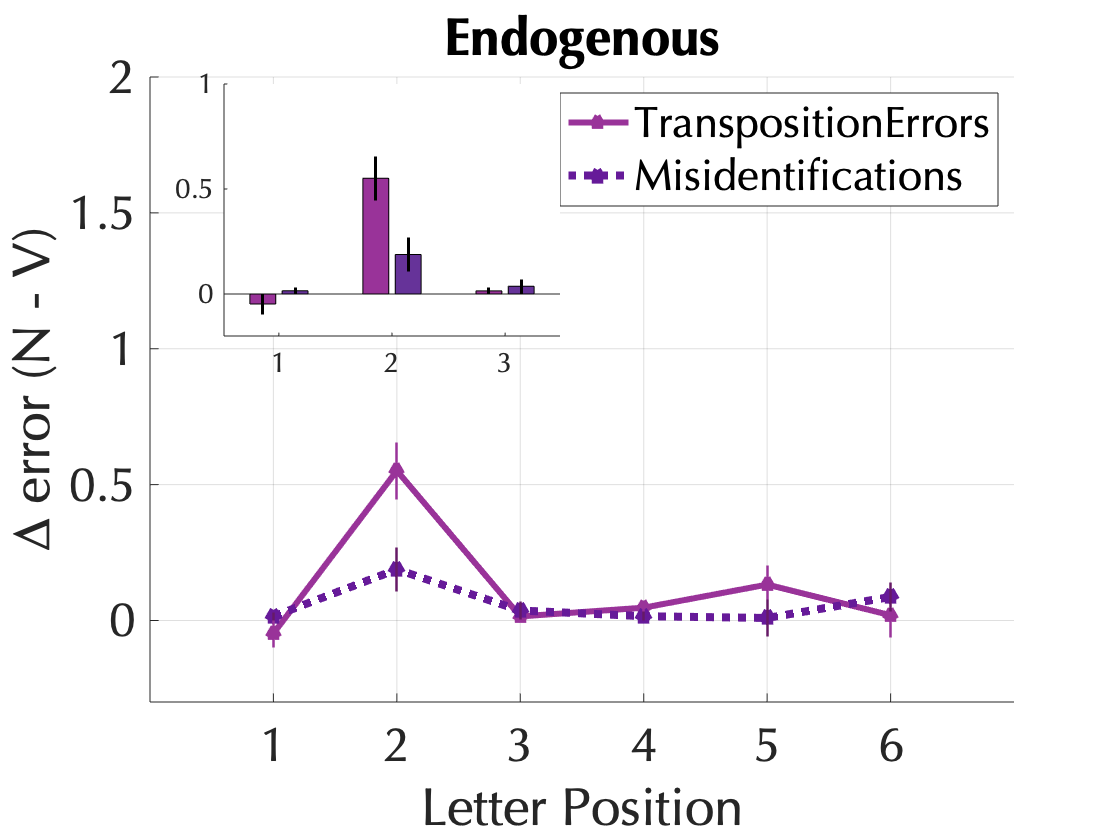

hold on 
for k=1:size(h,2)
        ctr(k,:) = bsxfun(@plus,h(1).XData, h(k).XOffset);
        ydt(k,:) = h(k).YData;
end
eh=errorbar(ctr',ydt',[errY_diffSwaps_crowded;errY_diffmisID_crowded]','-k','LineStyle','none','CapSize',0,'LineWidth',1.5,'Color',[0 0 0]);
h(1).FaceColor ='Flat' ; h(1).CData=[.6 0.2 .6];%h(1).FaceAlpha=0.1;
h(2).FaceColor ='Flat' ; h(2).CData=[.4 0.2 .6];
hold on 
xticklabels({'1','2','3'})
set(gca,'FontSize',14,'FontName','Optima')
 ylim([-0.2 1])
 box off

% legend({'Uncrowded position','Crowded position'})
clear ctr 
clear ydt
% Define crowded positions 
% err_Endo_600.crowdedPositions =[];
err_Endo_600.crowdedPositions(err_Endo_600.position=='2'| err_Endo_600.position=='5')=1;
err_Endo_600.crowdedPositions(err_Endo_600.position=='1'| err_Endo_600.position=='6' )=2; 
err_Endo_600.crowdedPositions=categorical(err_Endo_600.crowdedPositions);

y_diffSwaps_outer =  [mean(err_Endo_600.difSwap(err_Endo_600.crowdedPositions=='2')),mean(err_Endo_600.difSwap(err_Endo_600.crowdedPositions=='1'))];
errY_diffSwaps_outer =  [std(err_Endo_600.difSwap(err_Endo_600.crowdedPositions=='2')),std(err_Endo_600.difSwap(err_Endo_600.crowdedPositions=='1'))]./sqrt(size((err_Endo_600.difSwap(err_Endo_600.crowdedPositions=='1')),1));

y_diffmisID_outer =  [mean(err_Endo_600.difmisD(err_Endo_600.crowdedPositions=='2')),mean(err_Endo_600.difmisD(err_Endo_600.crowdedPositions=='1'))];
errY_diffmisID_outer =  [std(err_Endo_600.difmisD(err_Endo_600.crowdedPositions=='2')),std(err_Endo_600.difmisD(err_Endo_600.crowdedPositions=='1'))]./sqrt(size(err_Endo_600.difmisD(err_Endo_600.crowdedPositions=='1'),1));
[y_diffSwaps_outer; y_diffmisID_outer]'

ans =    -0.0142    0.0511
    0.3417    0.0985


figure;
h = bar([y_diffSwaps_outer; y_diffmisID_outer]')

h =   1×2 Bar array:

    Bar    Bar


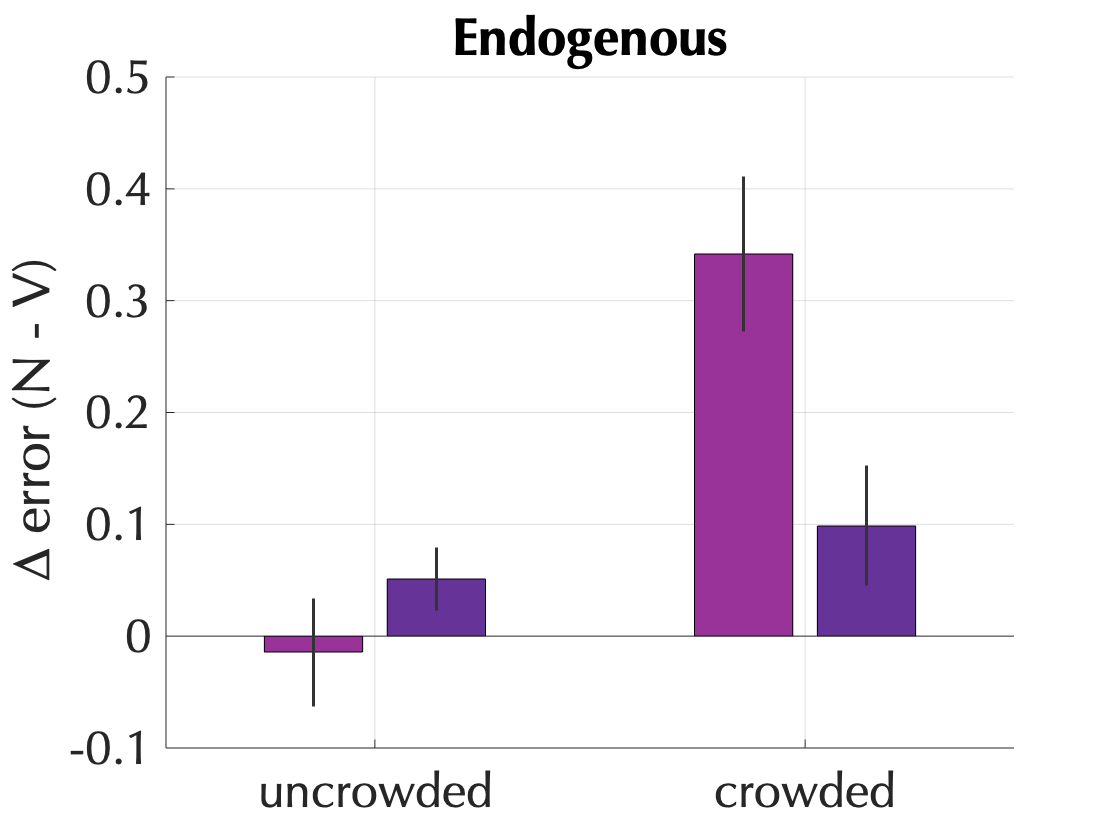

hold on 
for k=1:size(h,2)
        ctr(k,:) = bsxfun(@plus,h(1).XData, h(k).XOffset);
        ydt(k,:) = h(k).YData;
end
eh=errorbar(ctr',ydt',[errY_diffSwaps_outer;errY_diffmisID_outer]','-k','LineStyle','none','CapSize',0,'LineWidth',1.5,'Color',[.2 0.2 .2]);
h(1).FaceColor ='Flat' ; h(1).CData=[.6 0.2 .6];
h(2).FaceColor ='Flat' ; h(2).CData=[.4 0.2 .6];%h(2).FaceAlpha=0.1;
hold on 
ylabel '∆ error (N - V) '
xticklabels({'uncrowded','crowded'})
set(gca,'FontSize',24,'FontName','Optima')
ylim([-0.1 0.5])
title 'Endogenous'
grid on  
box off

clear ctr
clear ydt
%% EXO %%%%%--------------
% Transforming non-linear to linear data 
err_Exo_50.difSwap=(err_Exo_50.pSwaps_N-err_Exo_50.pSwaps_V);
err_Exo_50.difmisD=(err_Exo_50.misID_N-err_Exo_50.misID_V);

y_diffSwaps = [mean(err_Exo_50.difSwap(err_Exo_50.position=='1')),mean(err_Exo_50.difSwap(err_Exo_50.position=='2')),...
    mean(err_Exo_50.difSwap(err_Exo_50.position=='3')),mean(err_Exo_50.difSwap(err_Exo_50.position=='4')),mean(err_Exo_50.difSwap(err_Exo_50.position=='5')),...
    mean(err_Exo_50.difSwap(err_Exo_50.position=='6'))];
errYDswaps = [std(err_Exo_50.difSwap(err_Exo_50.position=='1')),std(err_Exo_50.difSwap(err_Exo_50.position=='2')),...
    std(err_Exo_50.difSwap(err_Exo_50.position=='3')),std(err_Exo_50.difSwap(err_Exo_50.position=='4')),std(err_Exo_50.difSwap(err_Exo_50.position=='5')),...
    std(err_Exo_50.difSwap(err_Exo_50.position=='6'))]./sqrt(size(err_Exo_50.difSwap(err_Exo_50.position=='1'),1));
y_diffmis = [mean(err_Exo_50.difmisD(err_Exo_50.position=='1')),mean(err_Exo_50.difmisD(err_Exo_50.position=='2')),...
    mean(err_Exo_50.difmisD(err_Exo_50.position=='3')),mean(err_Exo_50.difmisD(err_Exo_50.position=='4')),mean(err_Exo_50.difmisD(err_Exo_50.position=='5')),...
    mean(err_Exo_50.difmisD(err_Exo_50.position=='6'))];
errYDmis = [std(err_Exo_50.difmisD(err_Exo_50.position=='1')),std(err_Exo_50.difmisD(err_Exo_50.position=='2')),...
    std(err_Exo_50.difmisD(err_Exo_50.position=='3')),std(err_Exo_50.difmisD(err_Exo_50.position=='4')),std(err_Exo_50.difmisD(err_Exo_50.position=='5')),...
    std(err_Exo_50.difmisD(err_Exo_50.position=='6'))]./sqrt(size(err_Exo_50.difmisD(err_Exo_50.position=='1'),1));
figure; 
plot(y_diffSwaps,'^','MarkerSize',5,'LineWidth',3,'LineStyle',"-",'Color',[.6 0.2 .6])
hold on 
errorbar(y_diffSwaps, errYDswaps,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',[.6 0.2 .6]);
hold on 
plot(y_diffmis,'^','MarkerSize',5,'LineWidth',4,'LineStyle',":",'Color',[.4 0.1 .6])
hold on 
errorbar(y_diffmis, errYDmis,'LineStyle','none','CapSize',0,'LineWidth',1.2,'Color',[.4 0.1 .6]);
hold on 
xlim([0 7])
xticks(1:1:6)
ylabel '∆ error (N - V) z-scores'
xlabel 'Letter Position' 
set(gca,'FontSize',24,'FontName','Optima')
title 'Exogenous'
ylim([-.3 2])
grid on 
hold on 
box off
clear ctr
clear ydt
%err_Exo_50.crowdedPositions=[];
err_Exo_50.crowdedPositions(err_Exo_50.position=='2' |err_Exo_50.position=='5')=1;
err_Exo_50.crowdedPositions(err_Exo_50.position=='1' |err_Exo_50.position=='6')=2;
err_Exo_50.crowdedPositions=categorical(err_Exo_50.crowdedPositions);
y_diffSwaps_crowded =  [mean(err_Exo_50.difSwap(err_Exo_50.position=='1')),mean(err_Exo_50.difSwap(err_Exo_50.position=='2')),mean(err_Exo_50.difSwap(err_Exo_50.position=='3'))];
errY_diffSwaps_crowded =  [std(err_Exo_50.difSwap(err_Exo_50.position=='1'))./sqrt(size(err_Exo_50.difSwap(err_Exo_50.position=='1'),1)),std(err_Exo_50.difSwap(err_Exo_50.position=='2'))./sqrt(size(err_Exo_50.difSwap(err_Exo_50.position=='2'),1)), std(err_Exo_50.difSwap(err_Exo_50.position=='3'))./sqrt(size(err_Exo_50.difSwap(err_Exo_50.position=='3'),1))];

y_diffmisID_crowded =  [mean(err_Exo_50.difmisD(err_Exo_50.position=='1')),mean(err_Exo_50.difmisD(err_Exo_50.position=='2')),mean(err_Exo_50.difmisD(err_Exo_50.position=='3'))]

y_diffmisID_crowded =    -0.0113    0.0899    0.1177


errY_diffmisID_crowded =  [std(err_Exo_50.difmisD(err_Exo_50.position=='1'))./sqrt(size((err_Exo_50.difmisD(err_Exo_50.position=='1')),1)),std(err_Exo_50.difmisD(err_Exo_50.position=='2'))./sqrt(size(err_Exo_50.difmisD(err_Exo_50.position=='2'),1)),std(err_Exo_50.difmisD(err_Exo_50.position=='3'))./sqrt(size(err_Exo_50.difmisD(err_Exo_50.position=='3'),1))];

axes('Position',[.2 .6 .3 .3])
h = bar([y_diffSwaps_crowded; y_diffmisID_crowded]')

h =   1×2 Bar array:

    Bar    Bar


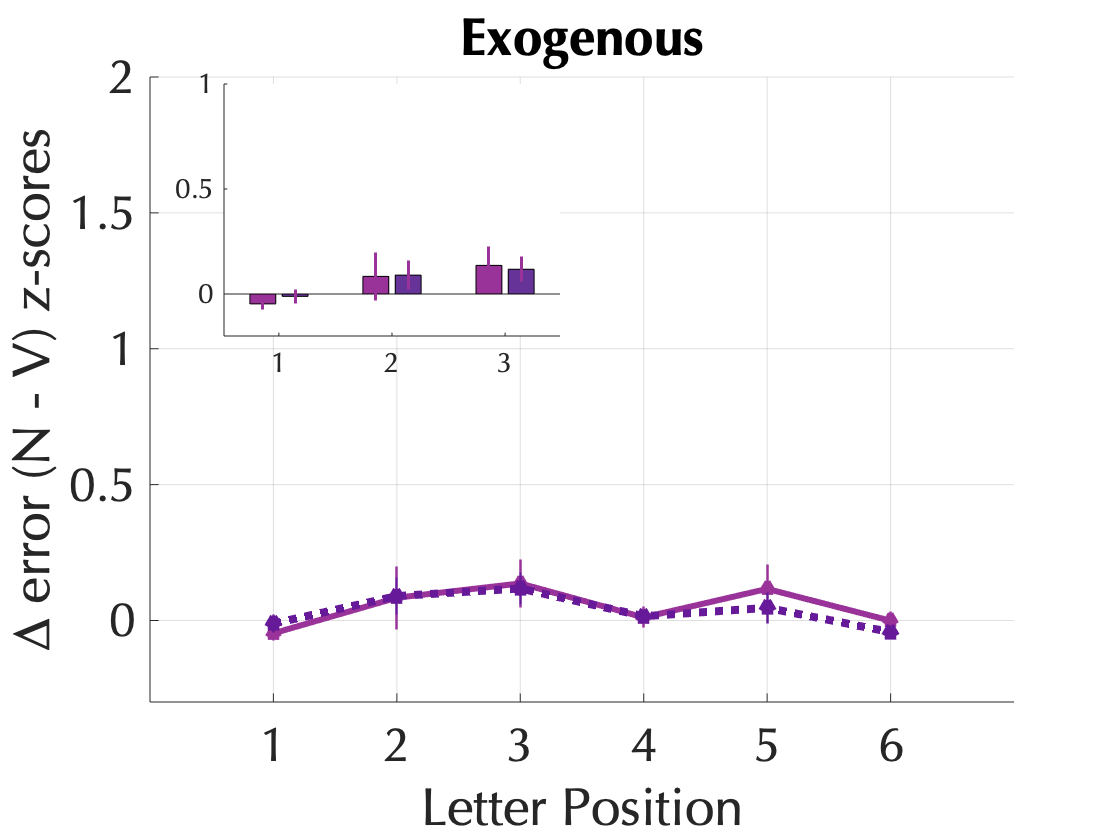

hold on 
for k=1:size(h,2)
        ctr(k,:) = bsxfun(@plus,h(1).XData, h(k).XOffset);
        ydt(k,:) = h(k).YData;
end
eh=errorbar(ctr',ydt',[errY_diffSwaps_crowded;errY_diffmisID_crowded]','-k','LineStyle','none','CapSize',0,'LineWidth',1.5,'Color',[.6 0.2 .6]);
h(1).FaceColor ='Flat' ; h(1).CData=[.6 0.2 .6];%h(1).FaceAlpha=0.1;
h(2).FaceColor ='Flat' ; h(2).CData=[.4 0.2 .6];
hold on 
xticklabels({'1','2','3'})
set(gca,'FontSize',14,'FontName','Optima')
ylim([-.2 1])
grid off 
box off

clear ctr
clear ydt

y_diffSwaps_outer =  [mean(err_Exo_50.difSwap(err_Exo_50.crowdedPositions=='2')),mean(err_Exo_50.difSwap(err_Exo_50.crowdedPositions=='1'))];
errY_diffSwaps_outer =  [std(err_Exo_50.difSwap(err_Exo_50.crowdedPositions=='2')),std(err_Exo_50.difSwap(err_Exo_50.crowdedPositions=='1'))]./sqrt(size((err_Exo_50.difSwap(err_Exo_50.crowdedPositions=='1')),1));

y_diffmisID_outer =  [mean(err_Exo_50.difmisD(err_Exo_50.crowdedPositions=='2')),mean(err_Exo_50.difmisD(err_Exo_50.crowdedPositions=='1'))];
errY_diffmisID_outer =  [std(err_Exo_50.difmisD(err_Exo_50.crowdedPositions=='2')),std(err_Exo_50.difmisD(err_Exo_50.crowdedPositions=='1'))]./sqrt(size((err_Exo_50.difmisD(err_Exo_50.crowdedPositions=='1')),1));

[y_diffSwaps_outer; y_diffmisID_outer]

ans =    -0.0240    0.1000
   -0.0270    0.0682


figure;
h = bar([y_diffSwaps_outer; y_diffmisID_outer]')

h =   1×2 Bar array:

    Bar    Bar


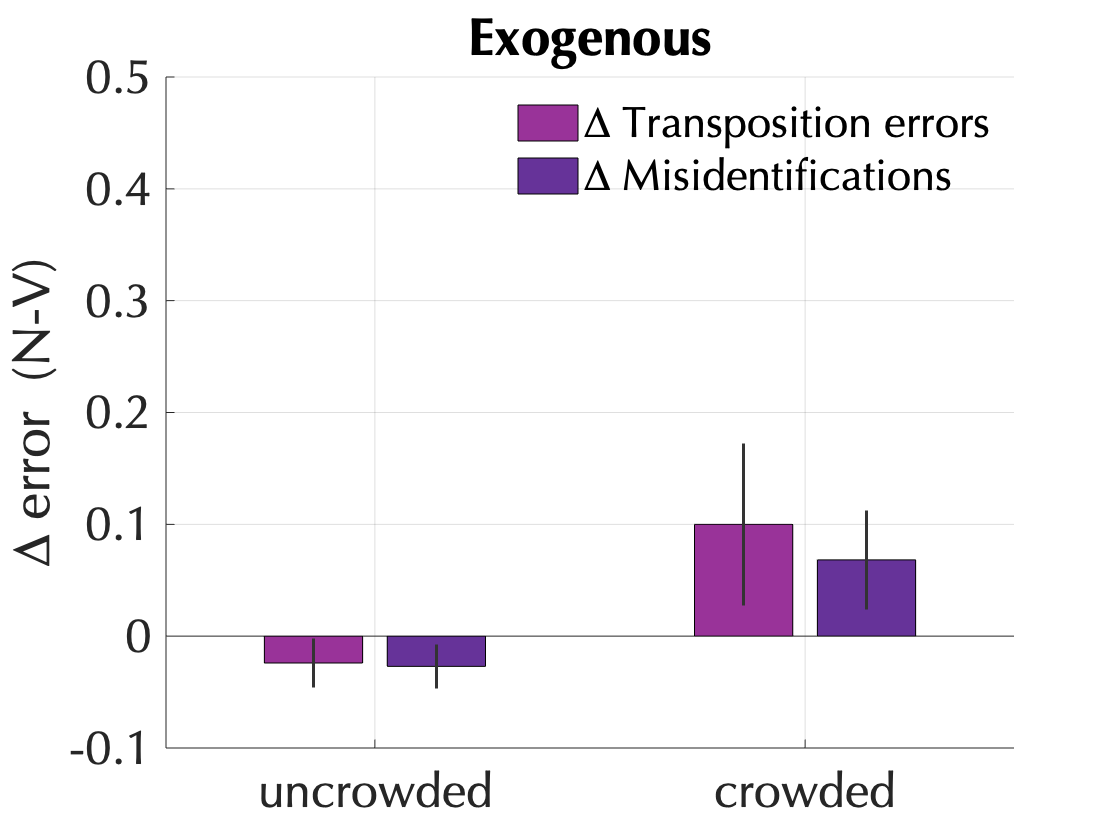

hold on 
for k=1:size(h,2)
        ctr(k,:) = bsxfun(@plus,h(1).XData, h(k).XOffset);
        ydt(k,:) = h(k).YData;
end
eh=errorbar(ctr',ydt',[errY_diffSwaps_outer;errY_diffmisID_outer]','-k','LineStyle','none','CapSize',0,'LineWidth',1.5,'Color',[.2 0.2 .2]);
h(1).FaceColor ='Flat' ; h(1).CData=[.6 0.2 .6];
h(2).FaceColor ='Flat' ; h(2).CData=[.4 0.2 .6];%h(2).FaceAlpha=0.7;
hold on 
ylabel '∆ error  (N-V)'
legend({'∆ Transposition errors','∆ Misidentifications'},"Box","off")
set(gca,'FontSize',24,'FontName','Optima')
ylim([-0.1 0.5])
xticklabels({'uncrowded','crowded'})
title 'Exogenous'
grid on  
box off

clear ctr
clear ydt

## Error Analysis

% Endo
lme19 = fitlme(err_Endo_600,'difSwap ~ position + (position | subID)',"DummyVarCoding","effects") % Stack the difference - code for positon swaps and misid (1,2) 

lme19 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             168
    Fixed effects coefficients           6
    Random effects coefficients        168
    Covariance parameters               22

Formula:
    difSwap ~ 1 + position + (1 + position | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    54.251    141.72    0.87468          -1.7494 

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF     pValue        Lower       Upper     
    {'(Intercept)'}          0.11951    0.023571     5.0703    162    1.0754e-06    0.072965       0.16606
    {'position_1' }         -0.16716    0.046142    -3.6227    162    0.00038979    -0.25827     -0.076039
    {'position_2' }          0.43179    0.091146     4.7374    162    4.7038e-06     0.25181       0.61178
    {'position_3' }       

anova(lme19)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        25.708    1      162    1.0754e-06
    {'position'   }        6.9138    5      162    7.0708e-06


lme20 = fitlme(err_Endo_600, 'difmisD ~ position +(position | subID)',"DummyVarCoding","effects")

lme20 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             168
    Fixed effects coefficients           6
    Random effects coefficients        168
    Covariance parameters               22

Formula:
    difmisD ~ 1 + position + (1 + position | subID)

Model fit statistics:
    AIC        BIC       LogLikelihood    Deviance
    -82.359    5.1117    69.18            -138.36 

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF     pValue      Lower        Upper     
    {'(Intercept)'}         0.058612    0.026246     2.2332    162    0.026908    0.0067834       0.11044
    {'position_1' }        -0.043243    0.027892    -1.5503    162     0.12301    -0.098323      0.011837
    {'position_2' }          0.12927    0.064569      2.002    162    0.046952    0.0017628       0.25678
    {'position_3' }         

anova(lme20)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue  
    {'(Intercept)'}         4.987    1      162    0.026908
    {'position'   }        2.8746    5      162    0.016277



err_Endo=stack(err_Endo_600,{'difSwap','difmisD'},'NewDataVariableName','errors');
err_Endo.errors_Indicator = categorical(err_Endo.errors_Indicator);

lme_20a = fitlme(err_Endo, 'errors ~errors_Indicator*position +(errors_Indicator*position | subID)',"DummyVarCoding","effects")

lme_20a = Linear mixed-effects model fit by ML

Model information:
    Number of observations             336
    Fixed effects coefficients          12
    Random effects coefficients        336
    Covariance parameters               79

Formula:
    errors ~ 1 + position*errors_Indicator + (1 + position*errors_Indicator | subID)

Model fit statistics:
    AIC       BIC      LogLikelihood    Deviance
    13.947    361.3    84.026           -168.05 

Fixed effects coefficients (95% CIs):
    Name                                           Estimate     SE          tStat       DF     pValue        Lower        Upper     
    {'(Intercept)'                        }         0.089061    0.016794      5.3031    324    2.1129e-07     0.056022        0.1221
    {'position_1'                         }          -0.1052     0.02422     -4.3436    324    1.8776e-05     -0.15285     -0.057552
    {'position_2'     

anova(lme_20a)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                                 FStat     DF1    DF2    pValue    
    {'(Intercept)'              }        28.122    1      324    2.1129e-07
    {'position'                 }        7.8936    5      324    4.9479e-07
    {'errors_Indicator'         }        2.7256    1      324      0.099719
    {'position:errors_Indicator'}        2.8721    5      324       0.01489


err_Endo.crowdedPositions = removecats(err_Endo.crowdedPositions,{'0'}); 
lme_20b = fitlme(err_Endo, 'errors ~errors_Indicator*crowdedPositions +(errors_Indicator*crowdedPositions | subID)',"DummyVarCoding","effects")

lme_20b = Linear mixed-effects model fit by ML

Model information:
    Number of observations             224
    Fixed effects coefficients           4
    Random effects coefficients        112
    Covariance parameters               11

Formula:
    errors ~ 1 + crowdedPositions*errors_Indicator + (1 + crowdedPositions*errors_Indicator | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    227.94    279.11    -98.968          197.94  

Fixed effects coefficients (95% CIs):
    Name                                                   Estimate    SE          tStat     DF     pValue        Lower         Upper   
    {'(Intercept)'                                }         0.11928    0.025831    4.6177    220    6.5996e-06      0.068371     0.17019
    {'crowdedPositions_1'                         }         0.10084    0.026964    3.7396    220    0.00023506      0.047695     

anova(lme_20b)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                                         FStat     DF1    DF2    pValue    
    {'(Intercept)'                      }        21.323    1      220    6.5996e-06
    {'crowdedPositions'                 }        13.985    1      220    0.00023506
    {'errors_Indicator'                 }        2.7046    1      220       0.10148
    {'crowdedPositions:errors_Indicator'}        5.9439    1      220      0.015561



lme21 = fitlme(err_Endo_600,'difSwap ~ crowdedPositions + (crowdedPositions|subID)','DummyVarCoding',"effects")

lme21 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             168
    Fixed effects coefficients           3
    Random effects coefficients         84
    Covariance parameters                7

Formula:
    difSwap ~ 1 + crowdedPositions + (1 + crowdedPositions | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    151.48    182.72    -65.739          131.48  

Fixed effects coefficients (95% CIs):
    Name                          Estimate     SE          tStat     DF     pValue        Lower       Upper    
    {'(Intercept)'       }          0.11951      0.0279    4.2835    165    3.1159e-05    0.064423       0.1746
    {'crowdedPositions_0'}        -0.088474    0.038669    -2.288    165       0.02341    -0.16482    -0.012123
    {'crowdedPositions_1'}          0.22218    0.051544    4.3104    165    2.7936e-05     0.12041    

anova(lme21)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                        FStat     DF1    DF2    pValue    
    {'(Intercept)'     }        18.348    1      165    3.1159e-05
    {'crowdedPositions'}        9.2927    2      165     0.0001499



lme22 = fitlme(err_Endo_600,'difmisD ~ crowdedPositions +(crowdedPositions | subID)','DummyVarCoding',"effects")

lme22 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             168
    Fixed effects coefficients           3
    Random effects coefficients         84
    Covariance parameters                7

Formula:
    difmisD ~ 1 + crowdedPositions + (1 + crowdedPositions | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    22.216    53.456    -1.108           2.216   

Fixed effects coefficients (95% CIs):
    Name                          Estimate     SE          tStat      DF     pValue      Lower        Upper   
    {'(Intercept)'       }         0.058612    0.026855     2.1826    165    0.030481    0.0055891     0.11163
    {'crowdedPositions_0'}        -0.032395    0.026414    -1.2264    165     0.22178    -0.084549    0.019758
    {'crowdedPositions_1'}          0.03993    0.040167    0.99409    165     0.32163    -0.039378     0.

anova(lme22)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                        FStat      DF1    DF2    pValue  
    {'(Intercept)'     }         4.7636    1      165    0.030481
    {'crowdedPositions'}        0.79075    2      165     0.45522



% Exo 
lme23 = fitlme(err_Exo_50,'difSwap ~ position +(position | subID)','DummyVarCoding',"effects") % Stack the difference - code for positon swaps and misid (1,2) 

lme23 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             168
    Fixed effects coefficients           6
    Random effects coefficients        168
    Covariance parameters               22

Formula:
    difSwap ~ 1 + position + (1 + position | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    95.376    182.85    -19.688          39.376  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF     pValue      Lower         Upper    
    {'(Intercept)'}         0.049941     0.02841     1.7579    162    0.080653    -0.0061596      0.10604
    {'position_1' }        -0.097077    0.041199    -2.3563    162    0.019654      -0.17843    -0.015721
    {'position_2' }         0.033857     0.10283    0.32926    162     0.74238       -0.1692      0.23691
    {'position_3' }         0.

anova(lme23)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue  
    {'(Intercept)'}        3.0902    1      162    0.080653
    {'position'   }        1.6783    5      162     0.14266


lme24 = fitlme(err_Exo_50, 'difmisD ~ position +(position | subID)','DummyVarCoding',"effects")

lme24 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             168
    Fixed effects coefficients           6
    Random effects coefficients        168
    Covariance parameters               22

Formula:
    difmisD ~ 1 + position + (1 + position | subID)

Model fit statistics:
    AIC        BIC       LogLikelihood    Deviance
    -31.983    55.488    43.992           -87.983 

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat       DF     pValue      Lower         Upper   
    {'(Intercept)'}         0.035938    0.019214      1.8704    162    0.063229    -0.0020038    0.073879
    {'position_1' }        -0.047267    0.029019     -1.6288    162     0.10529      -0.10457    0.010037
    {'position_2' }         0.053951    0.054355     0.99256    162      0.3224     -0.053385     0.16129
    {'position_3' }         

anova(lme24)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue  
    {'(Intercept)'}        3.4985    1      162    0.063229
    {'position'   }        3.3353    5      162    0.006793



err_Exo=stack(err_Exo_50,{'difSwap','difmisD'},'NewDataVariableName','errors');
err_Exo.errors_Indicator = categorical(err_Exo.errors_Indicator);
lme_24a = fitlme(err_Exo, 'errors ~ errors_Indicator*position +(errors_Indicator*position | subID)',"DummyVarCoding","effects")

lme_24a = Linear mixed-effects model fit by ML

Model information:
    Number of observations             336
    Fixed effects coefficients          12
    Random effects coefficients        336
    Covariance parameters               79

Formula:
    errors ~ 1 + position*errors_Indicator + (1 + position*errors_Indicator | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    61.058    408.42    60.471           -120.94 

Fixed effects coefficients (95% CIs):
    Name                                           Estimate      SE          tStat       DF     pValue       Lower          Upper    
    {'(Intercept)'                        }          0.042939    0.013528      3.1742    324    0.0016465       0.016327     0.069552
    {'position_1'                         }         -0.072172    0.025732     -2.8048    324    0.0053392       -0.12279    -0.021549
    {'position_2'

anova(lme_24a)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                                 FStat      DF1    DF2    pValue    
    {'(Intercept)'              }         10.076    1      324     0.0016465
    {'position'                 }         4.7125    5      324    0.00036066
    {'errors_Indicator'         }        0.12101    1      324       0.72817
    {'position:errors_Indicator'}        0.44375    5      324       0.81774



err_Exo.crowdedPositions = removecats(err_Exo.crowdedPositions,{'0'}); 
lme_24b = fitlme(err_Exo, 'errors ~ errors_Indicator*crowdedPositions +(errors_Indicator*crowdedPositions | subID)',"DummyVarCoding","effects")

lme_24b = Linear mixed-effects model fit by ML

Model information:
    Number of observations             224
    Fixed effects coefficients           4
    Random effects coefficients        112
    Covariance parameters               11

Formula:
    errors ~ 1 + crowdedPositions*errors_Indicator + (1 + crowdedPositions*errors_Indicator | subID)

Model fit statistics:
    AIC       BIC      LogLikelihood    Deviance
    122.02    173.2    -46.011          92.022  

Fixed effects coefficients (95% CIs):
    Name                                                   Estimate     SE          tStat      DF     pValue      Lower        Upper   
    {'(Intercept)'                                }         0.029285    0.021012     1.3937    220     0.16481    -0.012126    0.070695
    {'crowdedPositions_1'                         }         0.054807    0.023417     2.3405    220    0.020156    0.0086561     0.100

anova(lme_24b)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                                         FStat       DF1    DF2    pValue  
    {'(Intercept)'                      }          1.9424    1      220     0.16481
    {'crowdedPositions'                 }          5.4777    1      220    0.020156
    {'errors_Indicator'                 }        0.094698    1      220     0.75858
    {'crowdedPositions:errors_Indicator'}        0.057837    1      220     0.81017



lme25= fitlme(err_Exo_50,'difSwap ~ crowdedPositions + (crowdedPositions | subID)','DummyVarCoding',"effects")

lme25 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             168
    Fixed effects coefficients           3
    Random effects coefficients         84
    Covariance parameters                7

Formula:
    difSwap ~ 1 + crowdedPositions + (1 + crowdedPositions | subID)

Model fit statistics:
    AIC       BIC      LogLikelihood    Deviance
    146.96    178.2    -63.481          126.96  

Fixed effects coefficients (95% CIs):
    Name                          Estimate    SE          tStat      DF     pValue     Lower        Upper  
    {'(Intercept)'       }        0.049941    0.030624     1.6308    165    0.10485    -0.010525    0.11041
    {'crowdedPositions_0'}        0.023868    0.051082    0.46725    165    0.64093    -0.076991    0.12473
    {'crowdedPositions_1'}        0.050076    0.064353    0.77815    165    0.43759    -0.076985    0.17714



anova(lme25)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                        FStat     DF1    DF2    pValue 
    {'(Intercept)'     }        2.6594    1      165    0.10485
    {'crowdedPositions'}        1.7511    2      165    0.17679


lme26= fitlme(err_Exo_50,'difmisD ~ crowdedPositions + (crowdedPositions | subID)','DummyVarCoding',"effects")

lme26 = Linear mixed-effects model fit by ML

Model information:
    Number of observations             168
    Fixed effects coefficients           3
    Random effects coefficients         84
    Covariance parameters                7

Formula:
    difmisD ~ 1 + crowdedPositions + (1 + crowdedPositions | subID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    26.422    57.662    -3.2112          6.4224  

Fixed effects coefficients (95% CIs):
    Name                          Estimate    SE          tStat     DF     pValue      Lower         Upper   
    {'(Intercept)'       }        0.035938    0.020144     1.784    165    0.076263    -0.0038366    0.075712
    {'crowdedPositions_0'}        0.030751    0.027298    1.1265    165      0.2616     -0.023148    0.084649
    {'crowdedPositions_1'}        0.032228    0.029798    1.0815    165     0.28104     -0.026607    0.09106

anova(lme26)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                        FStat     DF1    DF2    pValue  
    {'(Intercept)'     }        3.1826    1      165    0.076263
    {'crowdedPositions'}        2.8009    2      165     0.06365


%%

% Cannot run 3 way mixed effects since this table removes cuetype 0 - Ran
% the 3 way mixed effects on graph pad Prism - refer output there. 
CombinedErrors = [err_Endo;err_Exo];
theLME = fitlme(CombinedErrors, 'errors ~ errors_Indicator*crowdedPositions +(errors_Indicator*crowdedPositions | subID)',"DummyVarCoding","effects");
anova(theLME)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                                         FStat     DF1    DF2    pValue    
    {'(Intercept)'                      }        15.934    1      444    7.6743e-05
    {'crowdedPositions'                 }        19.073    1      444    1.5676e-05
    {'errors_Indicator'                 }        1.6936    1      444        0.1938
    {'crowdedPositions:errors_Indicator'}        4.1347    1      444      0.042606



%The two way interactions are similar here. 
% F values are similar to that from Prism graph pad (double checked!) but
% the F values are not precisely matched 
theLME2 = fitlme(CombinedErrors, 'errors ~ cueType*errors_Indicator*crowdedPositions +(cueType*errors_Indicator*crowdedPositions | subID)',"DummyVarCoding","effects");
anova(theLME2)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                                                 FStat      DF1    DF2    pValue    
    {'(Intercept)'                              }         15.662    1      440    8.8283e-05
    {'cueType'                                  }         8.0411    1      440     0.0047837
    {'crowdedPositions'                         }          20.54    1      440    7.5344e-06
    {'errors_Indicator'                         }         1.7899    1      440       0.18163
    {'cueType:crowdedPositions'                 }         1.4205    1      440       0.23396
    {'cueType:errors_Indicator'                 }        0.83931    1      440        0.3601
    {'crowdedPositions:errors_Indicator'        }         4.3557    1      440      0.037461
    {'cueType:crowdedPositions:errors_Indicator'}         2.2009    1      440       0.13865



% now F values match!!! this is the correct model
theLME3 = fitlme(CombinedErrors, 'errors ~ cueType*errors_Indicator*crowdedPositions +(crowdedPositions | subID)',"DummyVarCoding","effects");
anova(theLME3)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                                                 FStat     DF1    DF2    pValue    
    {'(Intercept)'                              }        16.071    1      440     7.167e-05
    {'cueType'                                  }        7.1579    1      440     0.0077416
    {'crowdedPositions'                         }        18.661    1      440    1.9314e-05
    {'errors_Indicator'                         }        2.5006    1      440       0.11452
    {'cueType:crowdedPositions'                 }        1.8726    1      440       0.17188
    {'cueType:errors_Indicator'                 }        1.1294    1      440        0.2885
    {'crowdedPositions:errors_Indicator'        }         6.282    1      440      0.012557
    {'cueType:crowdedPositions:errors_Indicator'}        4.3184    1      440      0.038281


% For multiple comparisons I used GRaph pad out put - it was getting
% confusing here. 
